David Nichols

Project 2

12/6/2022

801101888

## **Part 1**

clc;
which myfft.m -all;

C:\Users\alway\Documents\GitHub\DSP\Project 2\myfft.m


which myifft.m -all;

C:\Users\alway\Documents\GitHub\DSP\Project 2\myifft.m


warning off

load('C.mat')
load('Ell.mat')
load('Least.mat')
load('butter.mat')
load('B_Rect.mat')
load('B_Hann.mat')

%setup for N and x_n
N = 6;
n = 0:1:N-1;
x_n = transpose(cos((pi/3).*n));

%find fourier transform
X_k = myfft(x_n)

X_k =   -0.0000 + 0.0000i
   3.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   3.0000 - 0.0000i


X_K_Checking = fft(x_n)

X_K_Checking =   -0.0000 + 0.0000i
   3.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   3.0000 + 0.0000i


X_k_ifft = myifft(X_k)

X_k_ifft =    6.0000 - 0.0000i
   3.0000 - 0.0000i
  -3.0000 + 0.0000i
  -6.0000 + 0.0000i
  -3.0000 + 0.0000i
   3.0000 - 0.0000i


error = sum(real(x_n - X_k_ifft)) %e-15 error need to check if thats acceptable

error = 8.8818e-15

As you can see from above, the myfft.m file works due to having the same values as the built in function.

Task 2

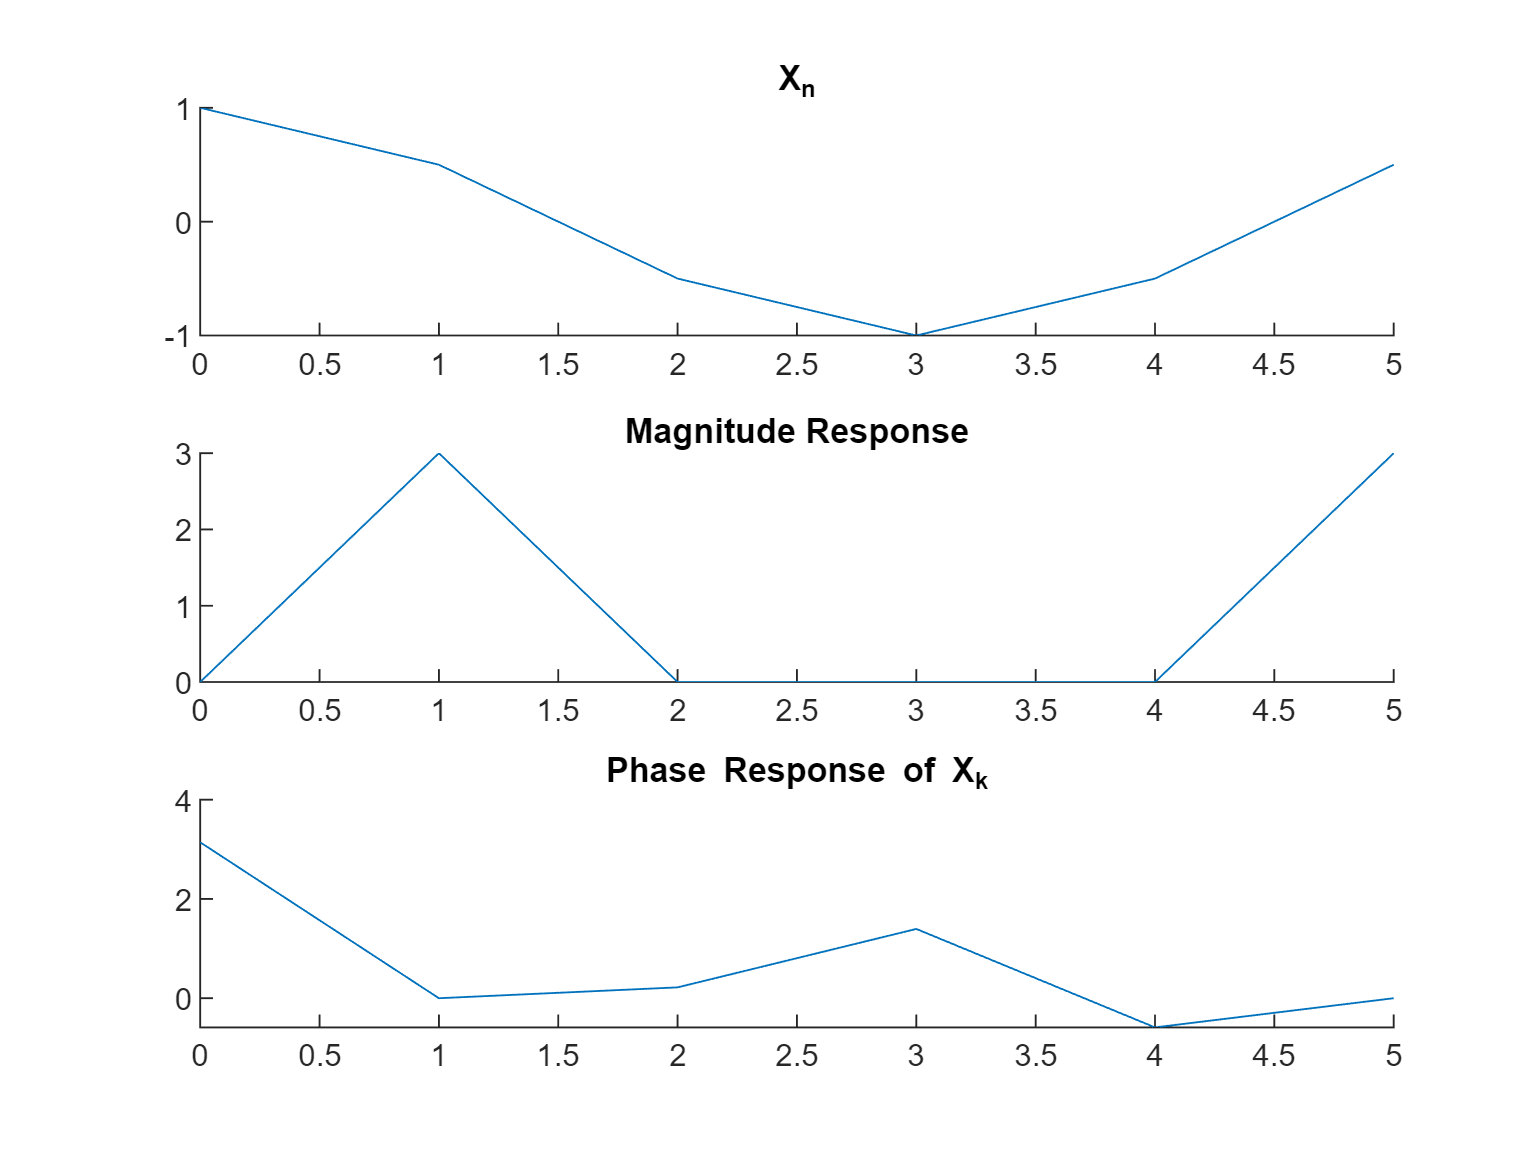

figure(1)
subplot(3,1,1)
hold on
plot(n,x_n)
title("X_n")

subplot(3,1,2);
hold on
title('Magnitude Response');
plot(n,abs(X_k));

subplot(3,1,3);
hold on
title('Phase Response of X_k')
plot(n,angle(X_k));

Task 3

**Explain the following: For each index k, explain the (possibly complex) observed value of the DFT, X[k], in terms of the magnitude and phase of the complex number (there are 5 such numbers)**

Answer: At every index K  we can see the imaginary and real parts that are then added to make the full signal. The magnitude reponse which is just the real part of the signal, shows the signal reaching a value of 3 at 1 and 5. Then at those same indexes the phase response is 0.

Task 4

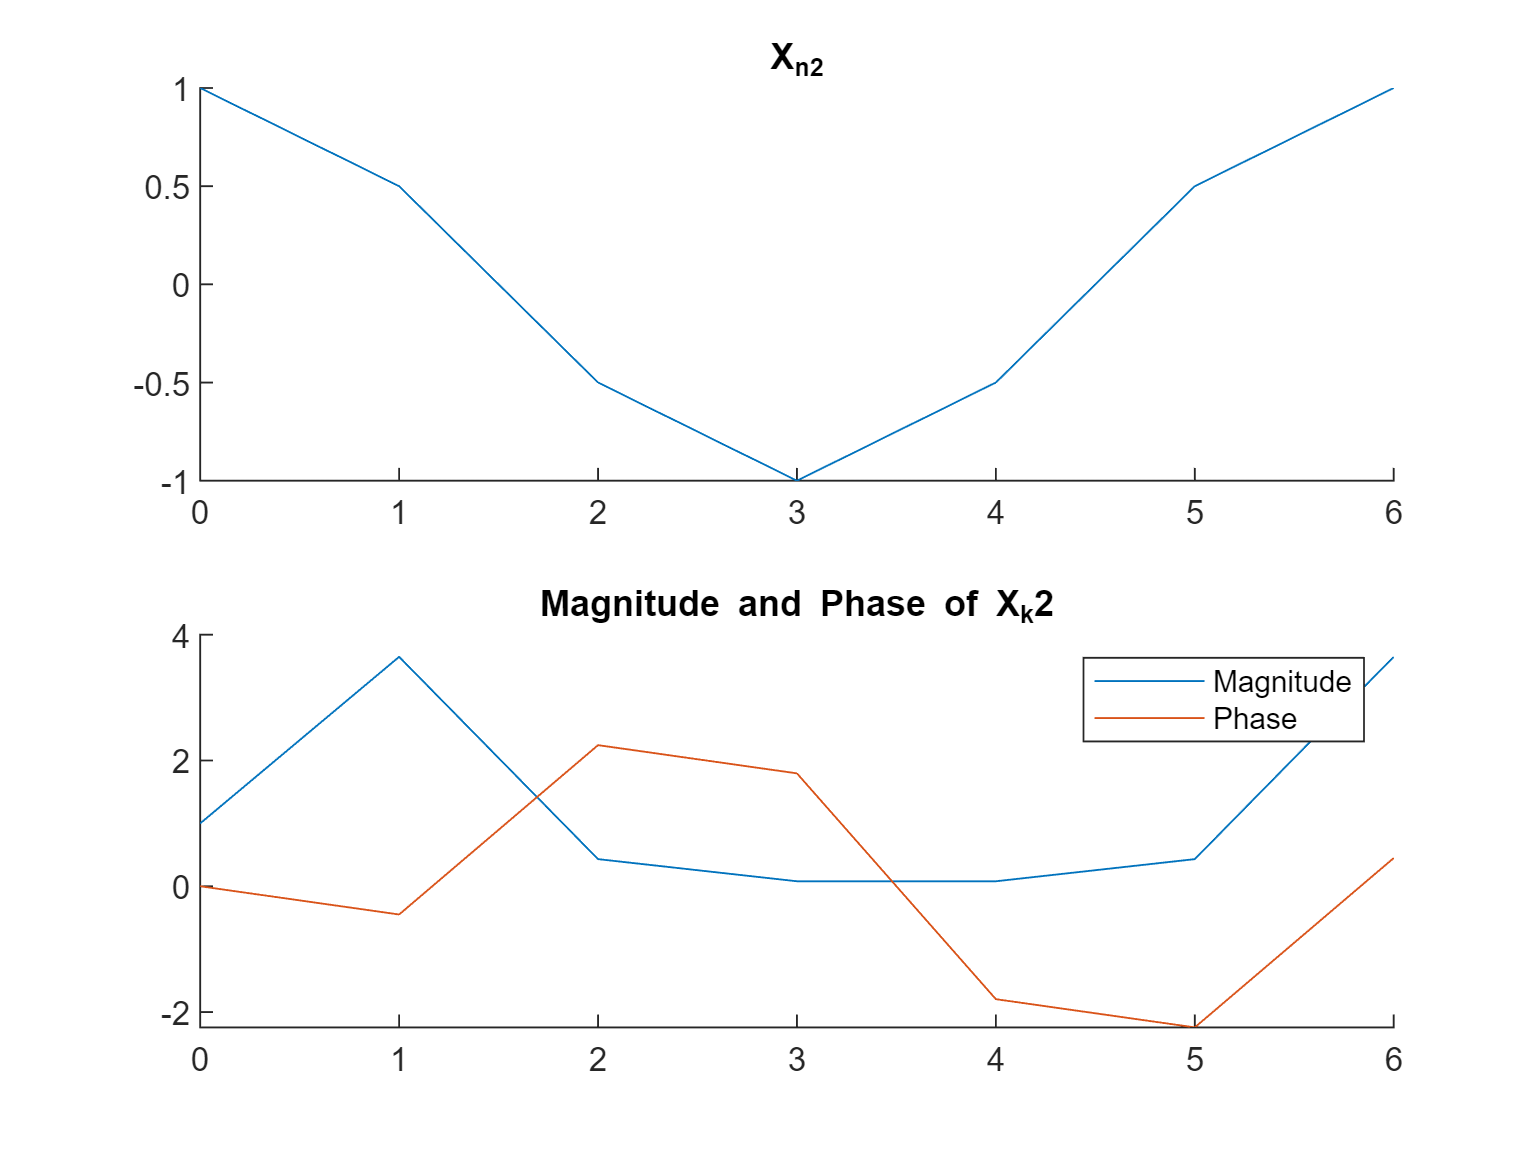

N=7;
n = 0:1:N-1;

x_n2 = transpose(cos((pi/3).*n));

x_k2 = myfft(x_n2);

figure(2)
subplot(2,1,1);
hold on
title('X_{n2}');
plot(n,x_n2);

subplot(2,1,2);
hold on
title('X_k2');
plot(n,abs(x_k2));
title('Magnitude and Phase of X_k2')
plot(n,angle(x_k2))
legend('Magnitude', 'Phase')

Task 5

**Explain why the DFT from steps (2) and (4) are different.**

Answer: Due to N=7 instead of N=6, the range of the signal is larger. The period between the two different DFTs are different as well. This increase causes the DFT to have a larger matrix and thus be more complex. The larger DFT signal contains more data than the smaller DFT signal. Also using the myfft function, the N is used to divide and due to the larger N the values at each index are changed.

Task 6 and 7

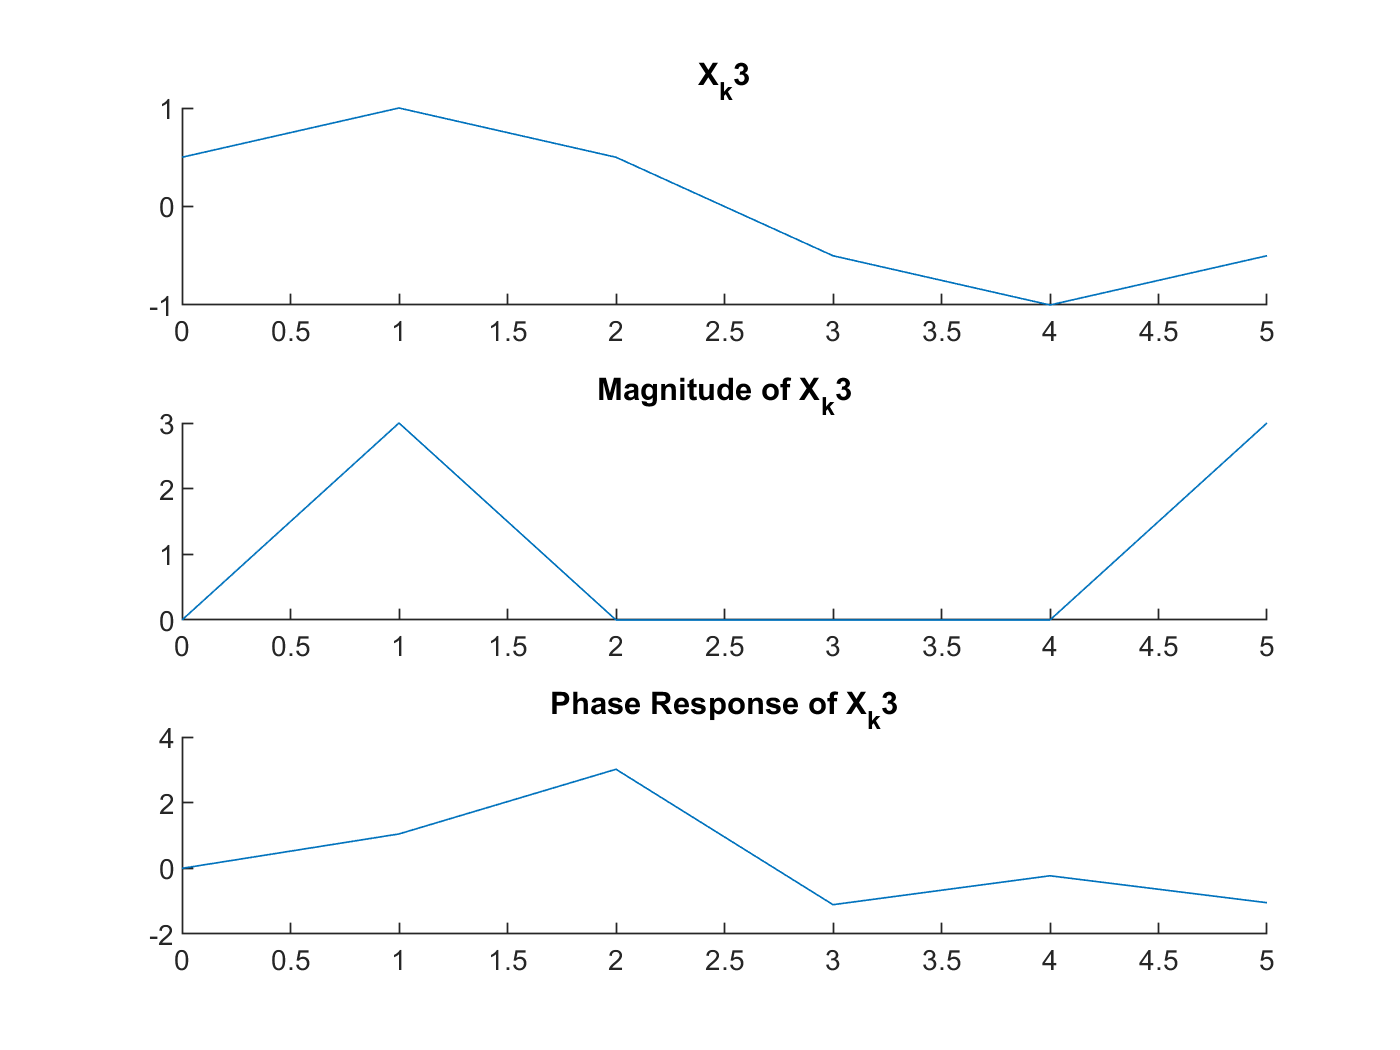

N=6; %Phase shifted
n = 0:1:N-1;

x_n3 = transpose(cos((pi/3).*(n-1)));

x_k3 = myfft(x_n3);

figure(3)
subplot(3,1,1);
hold on
title('X_k3');
plot(n,x_n3);
subplot(3,1,2);
hold on
title('Magnitude of X_k3')
plot(n,abs(x_k3));

subplot(3,1,3);
hold on
title('Phase Response of X_k3')
plot(n,angle(x_k3));
hold off

Task 8

**Explain why the DFT from steps (2) and (7) are different.**

Answer: The only different in the DFT from step 2 and step 7 is that the phase is shifted by n-1. This causes the magnitude response to be unchanged and the phase response to be changed. This causes the signal to be shifted.

Task 9

**For a sinusoidal sequence x[n] = cos(n) 0 ≤n ≤N . Determine if there is a value for N which makes the magnitude response |X[k]| zero everywhere except for two indices of k as in Task 1, step (2). Write a paragraph explaining your solution and show a plot of your results.**

Answer: To produce the graph below, N is required to be a non integer value. Specifically this value must be a multiple of pi/2. Thus there is no N that will produce $\cos \left\lbrack n\right\rbrack ;0\le n\le N$that will have zeros everywhere besides the two points at k. 

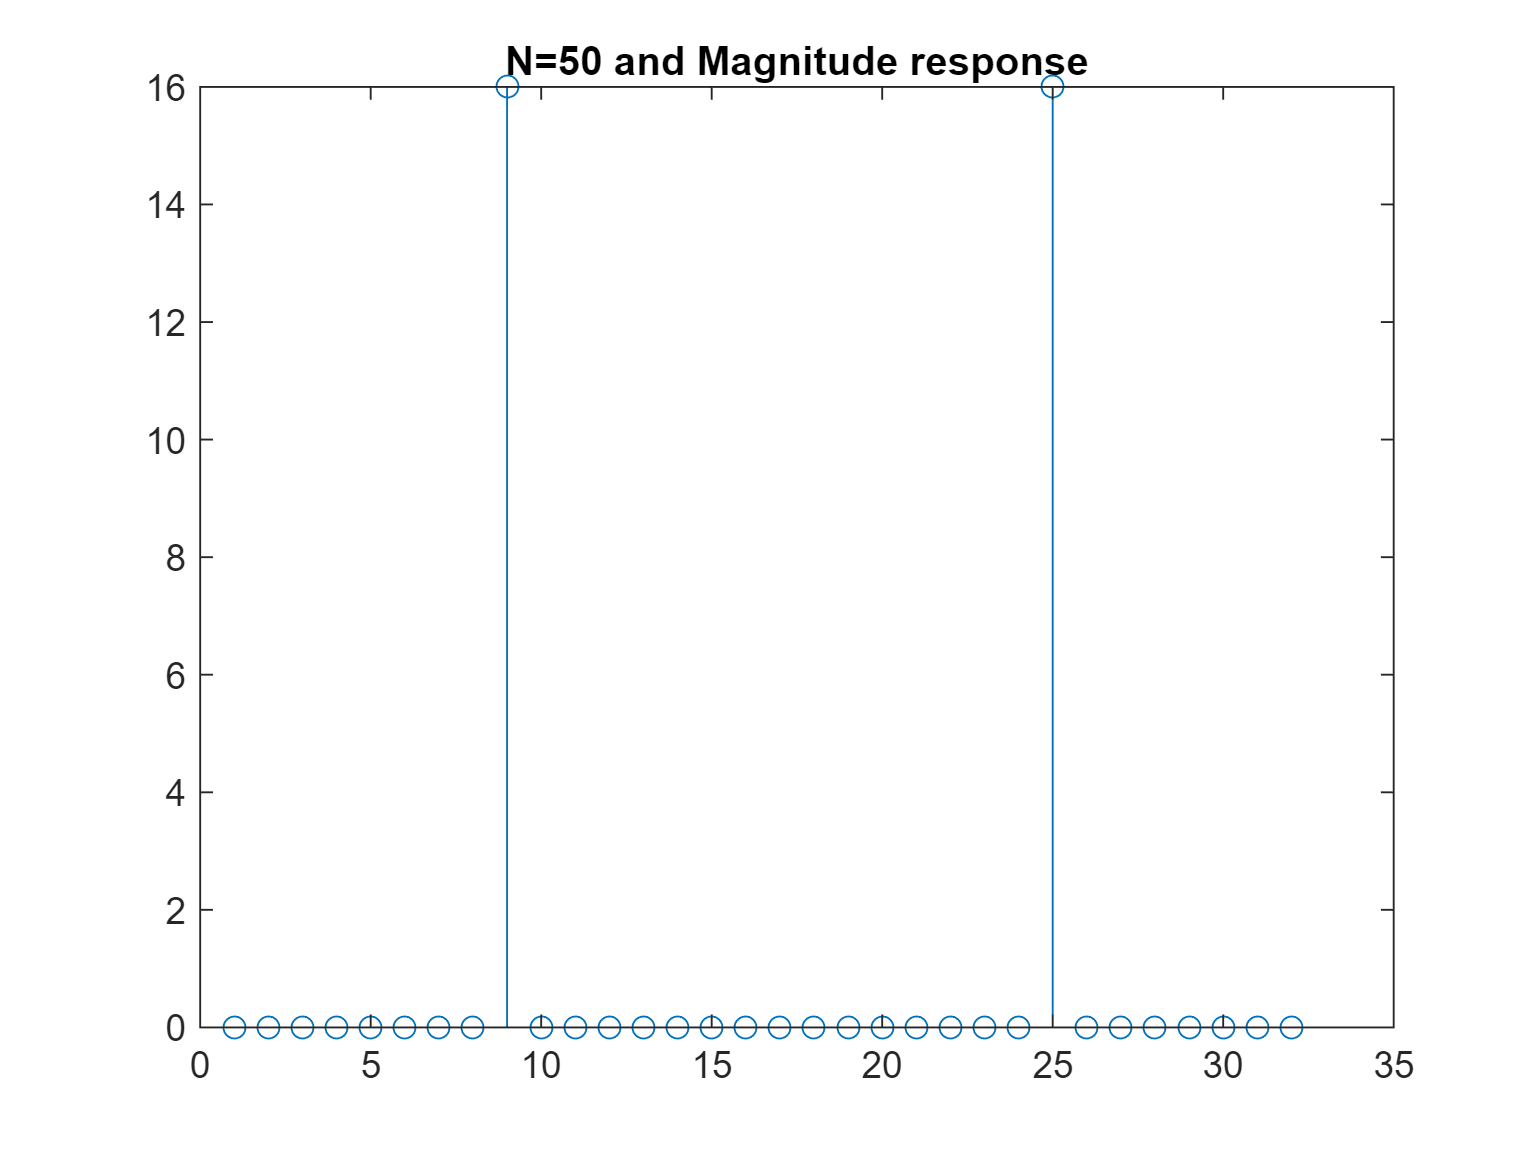

N=50;
n = 0:pi/2:N-1;
x_n4 = cos(n);
x_k4 = myfft(transpose(x_n4));
figure();
stem(abs(x_k4));
title("N=50 and Magnitude response")

## **Part 3**

Task 1

**For the Butterworth filter design of Steps 1-11, look at the coefficients of SOS and the coefficients of [a,b]. Indicate if one representation of the filter may be more desirable than the other. If so, why?**

The SOS and G coefficients are the transfer function coefficients, b and a. There is no best representation of the filter. This is due to the specifications of the filter. 

Task 2

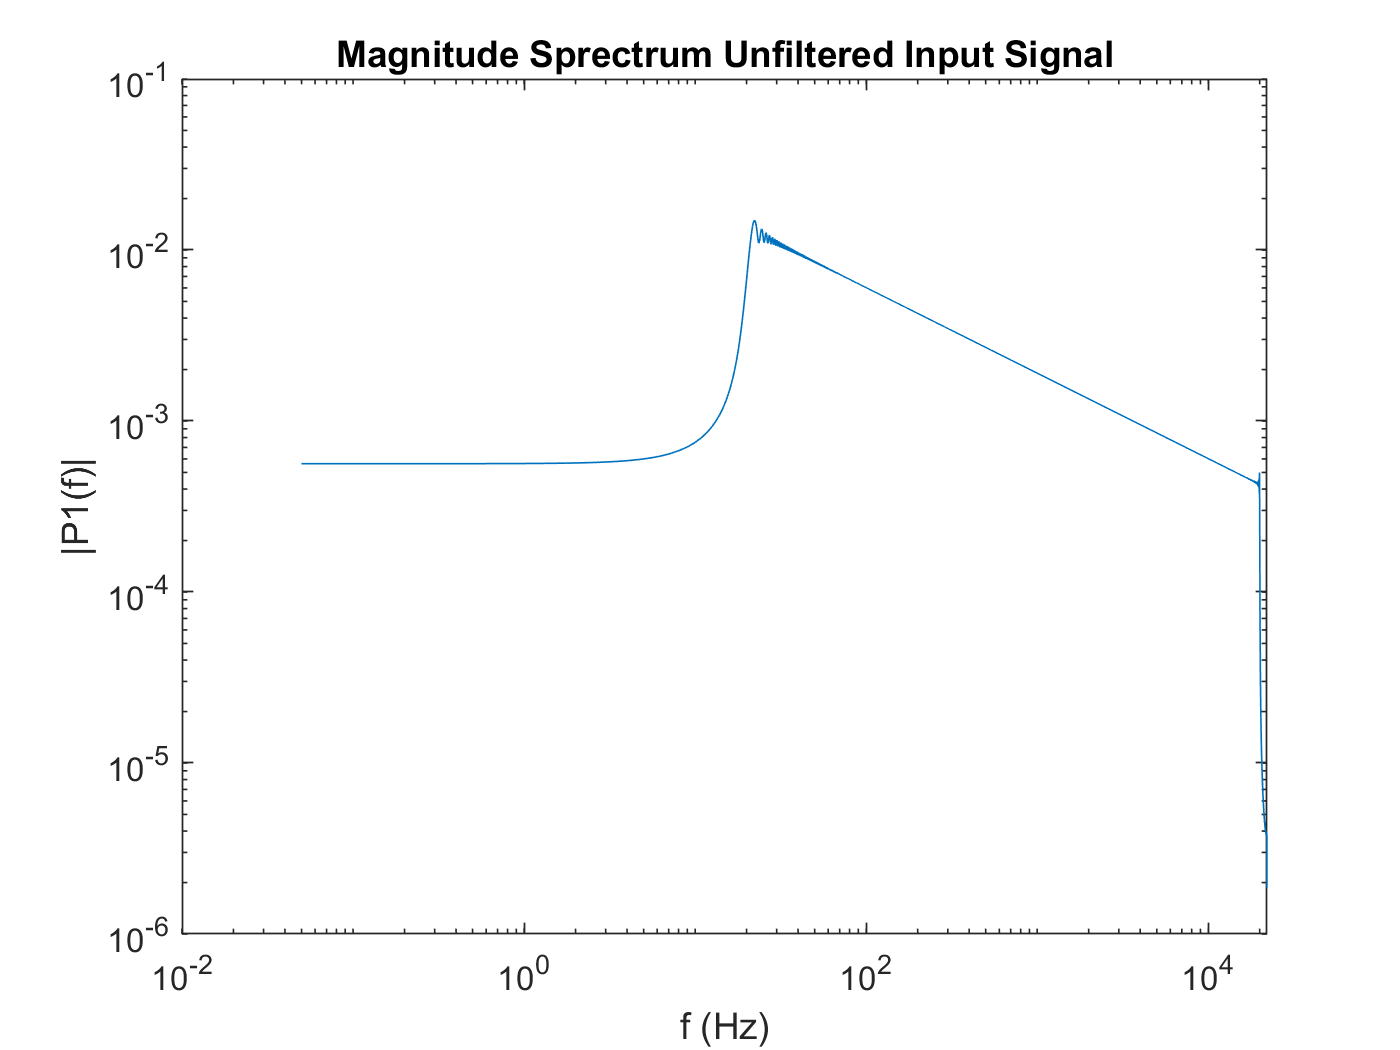

[x_log, fs_log] = audioread("audiocheck.net_sweep20-20klog.wav");
[x_lin, fs_lin] = audioread("audiocheck.net_sweep20-20klin.wav");
Fs = fs_log;          % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(x_log);    % Length of signal
t = (0:L-1)*T;        % Time vector
Y = fft(x_log);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
loglog(f,P1) 
title("Magnitude Sprectrum Unfiltered Input Signal")
xlabel("f (Hz)")
ylabel("|P1(f)|")

Task 2-5

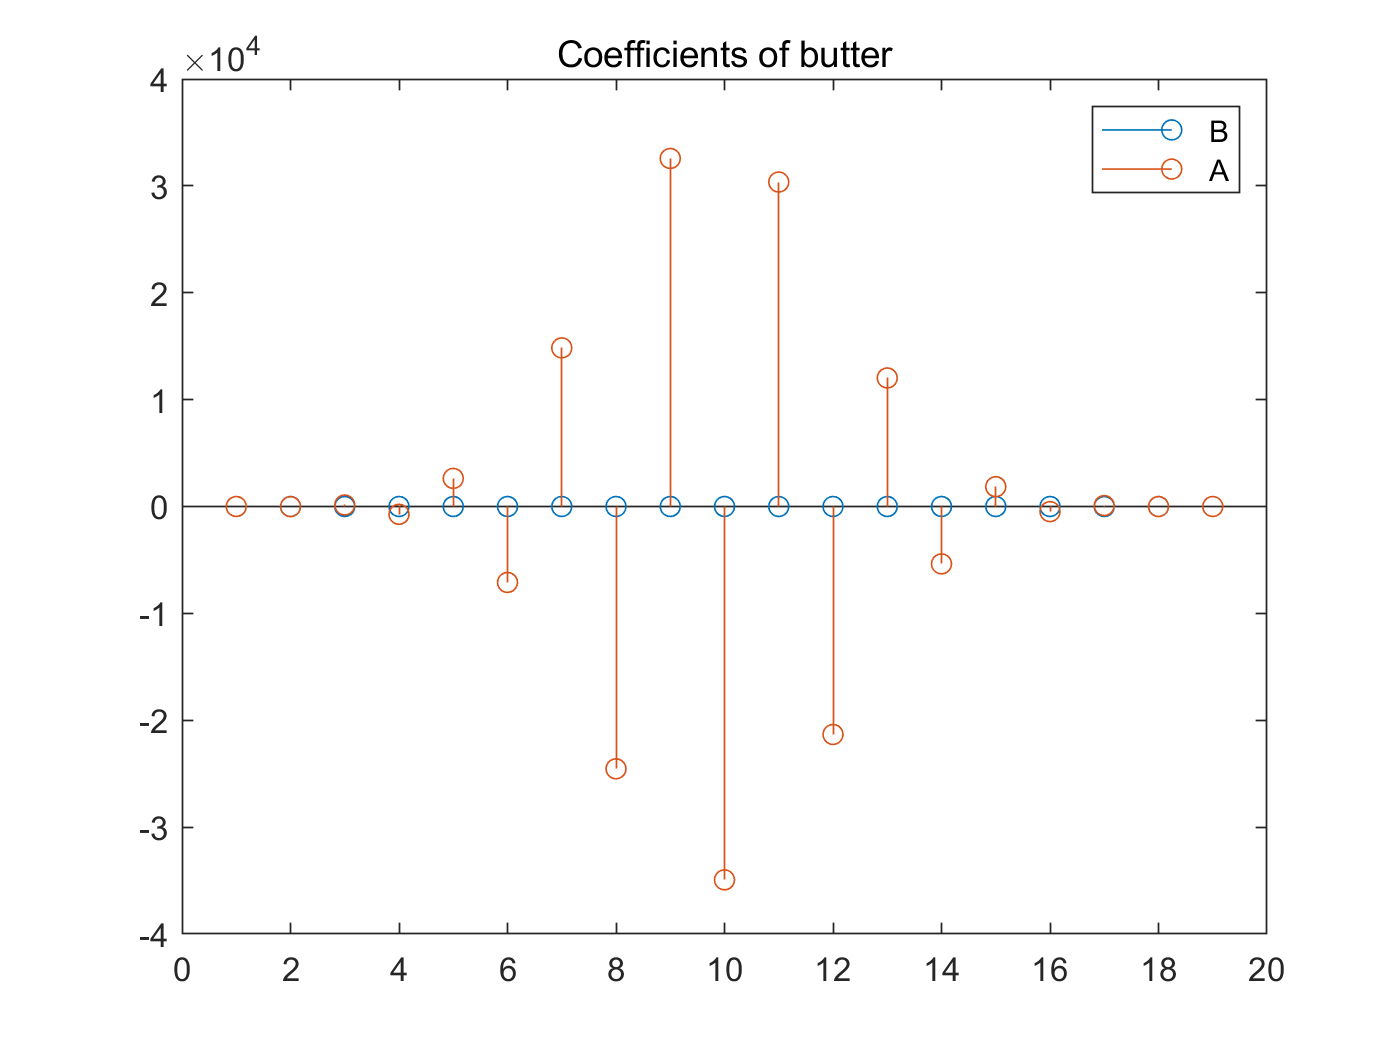

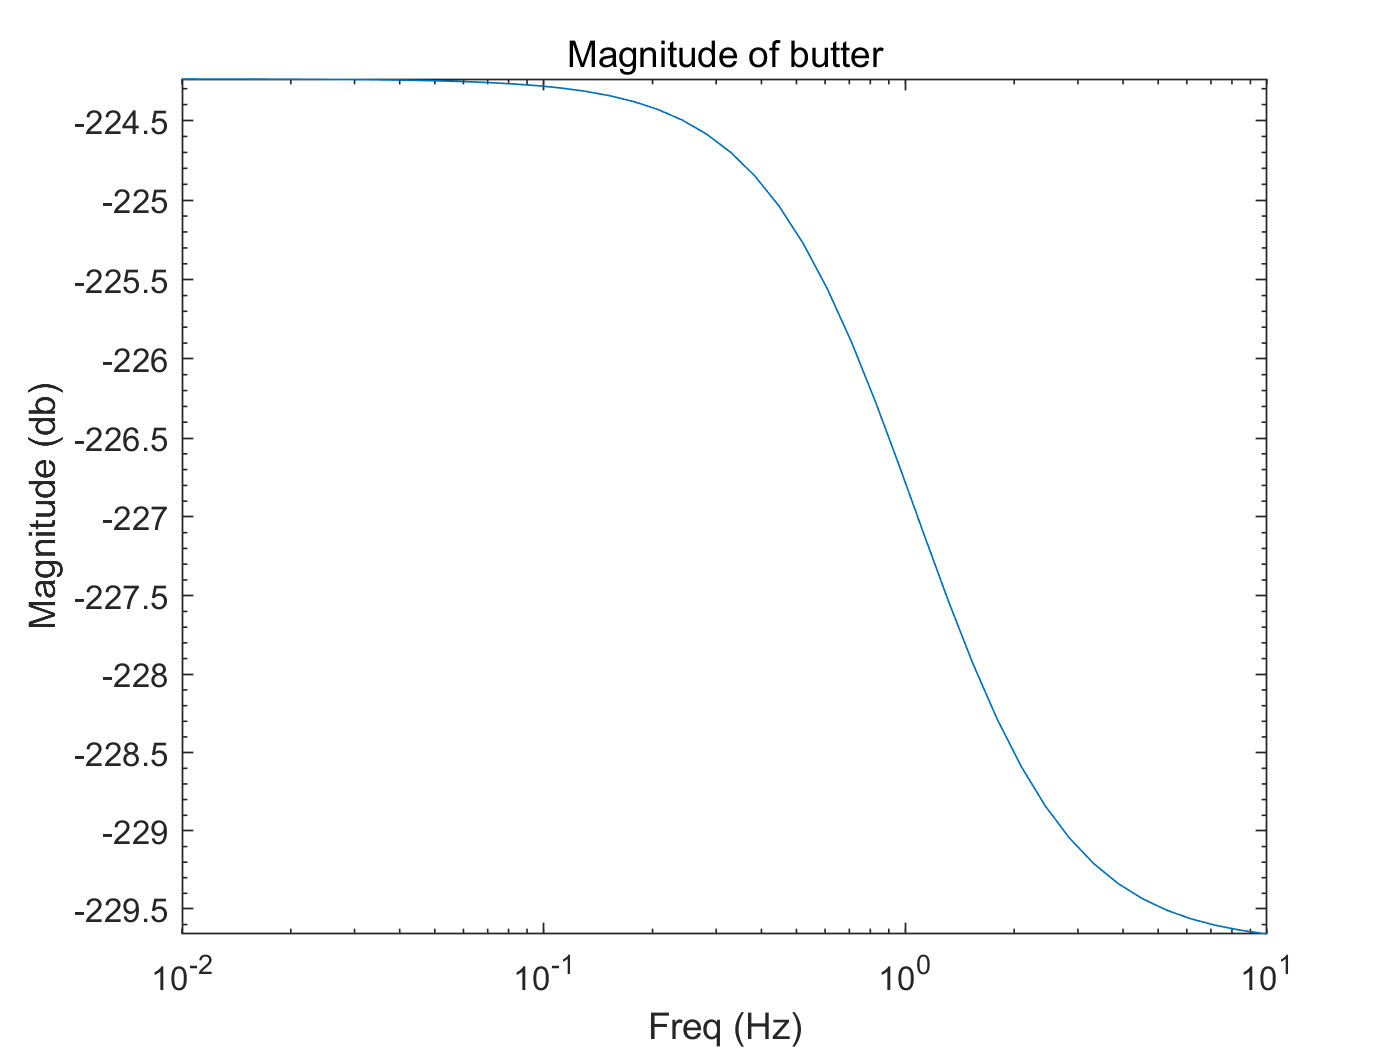

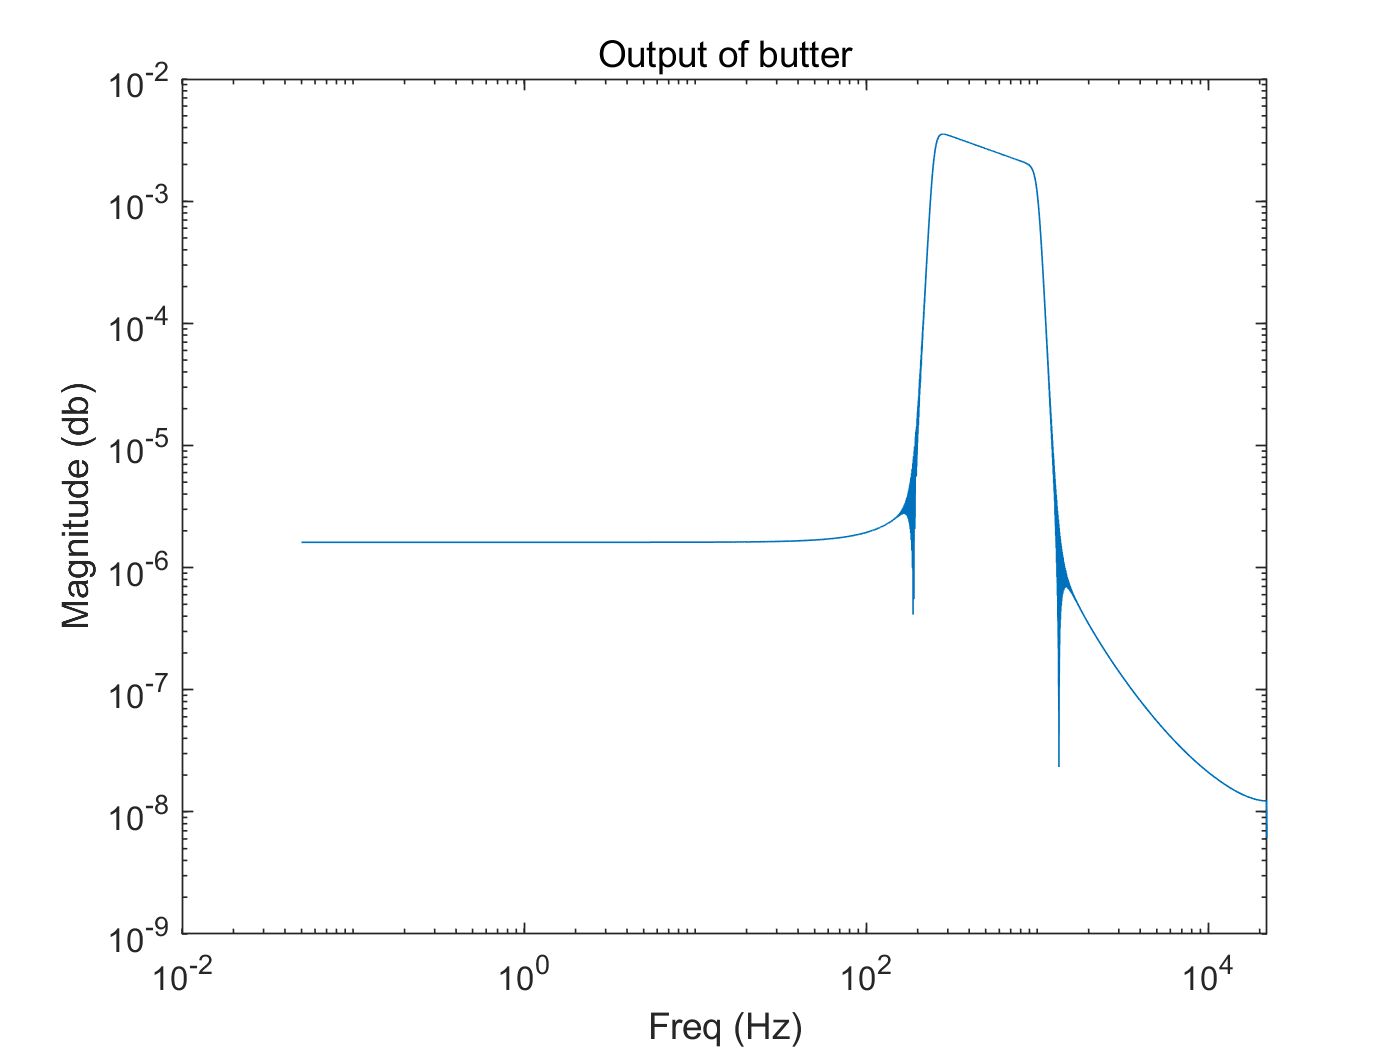

iir(SOS_butter, G_butter,"Butter")

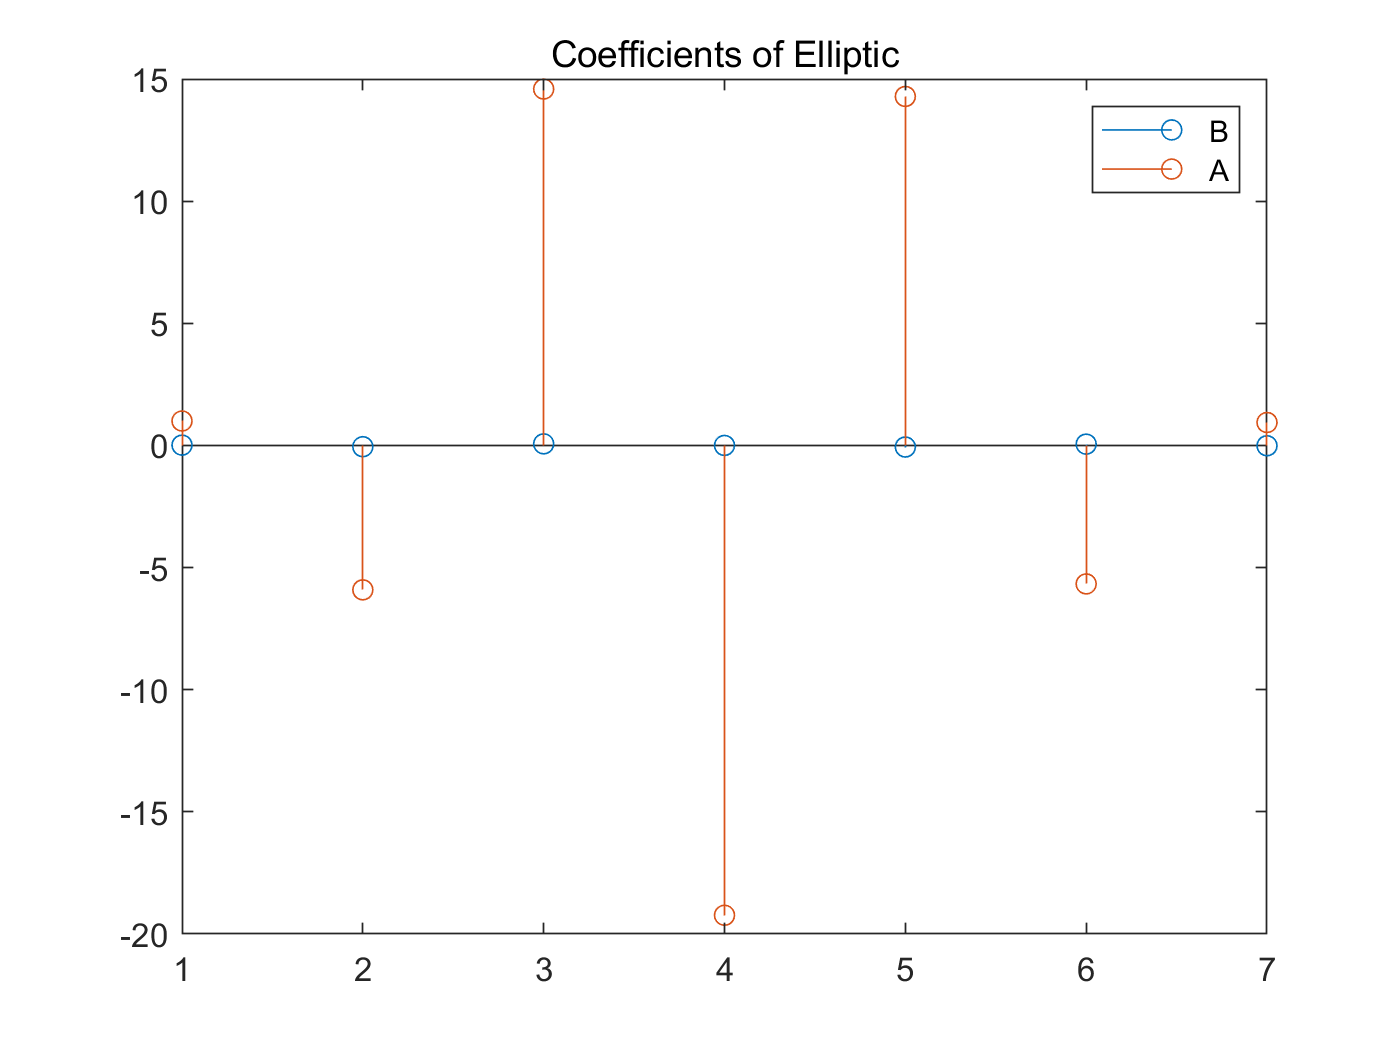

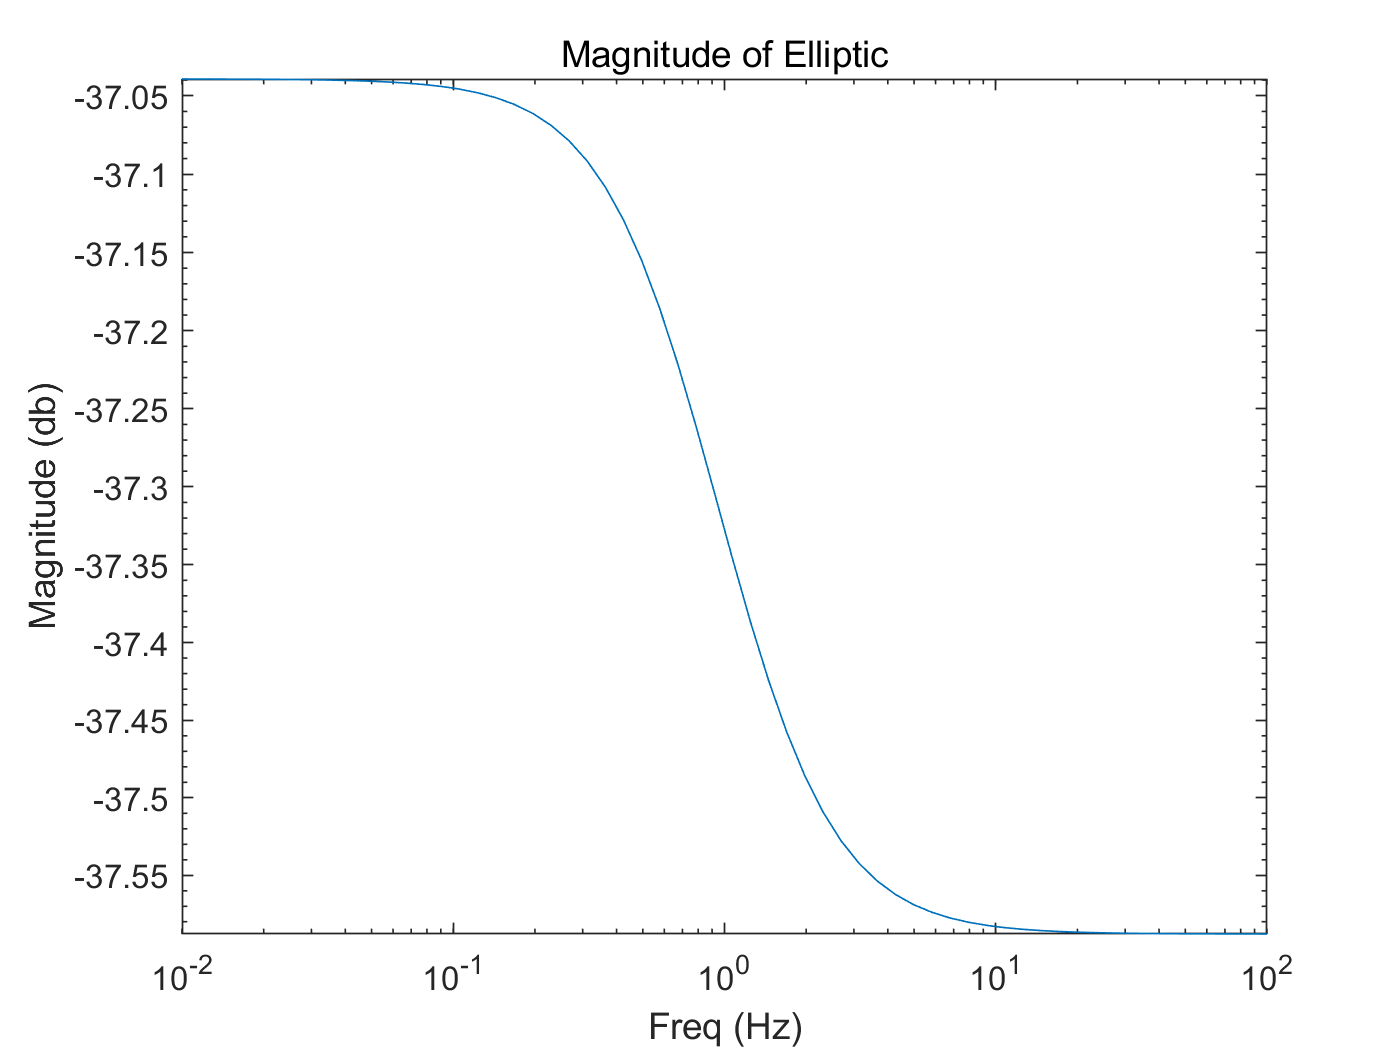

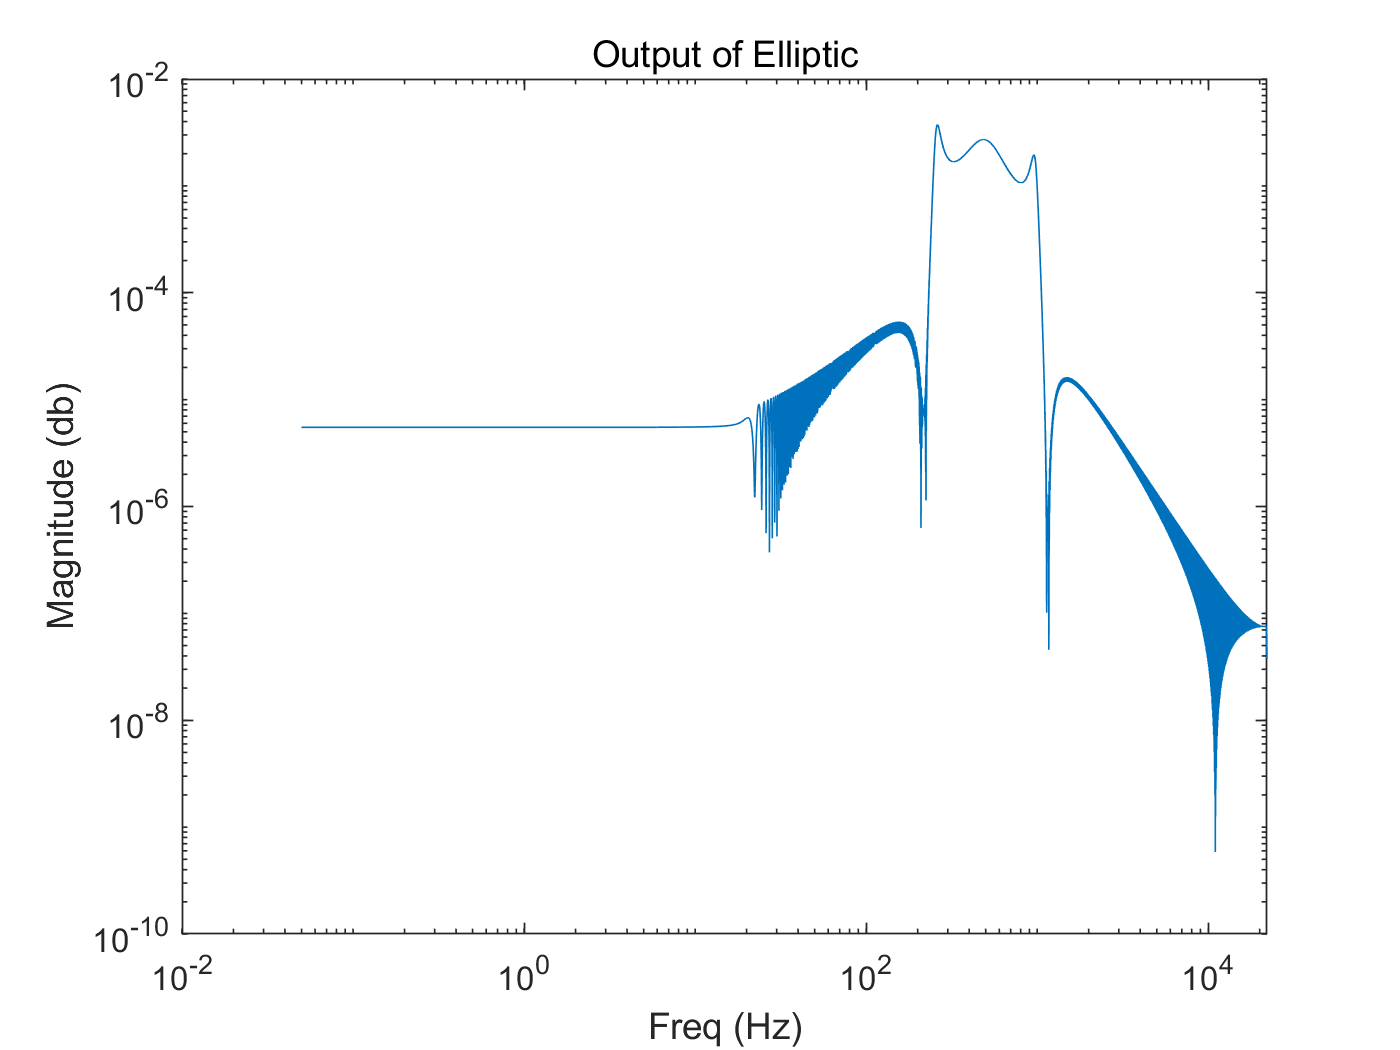

iir(SOS_Ell,G_Ell,"Elliptic"); 

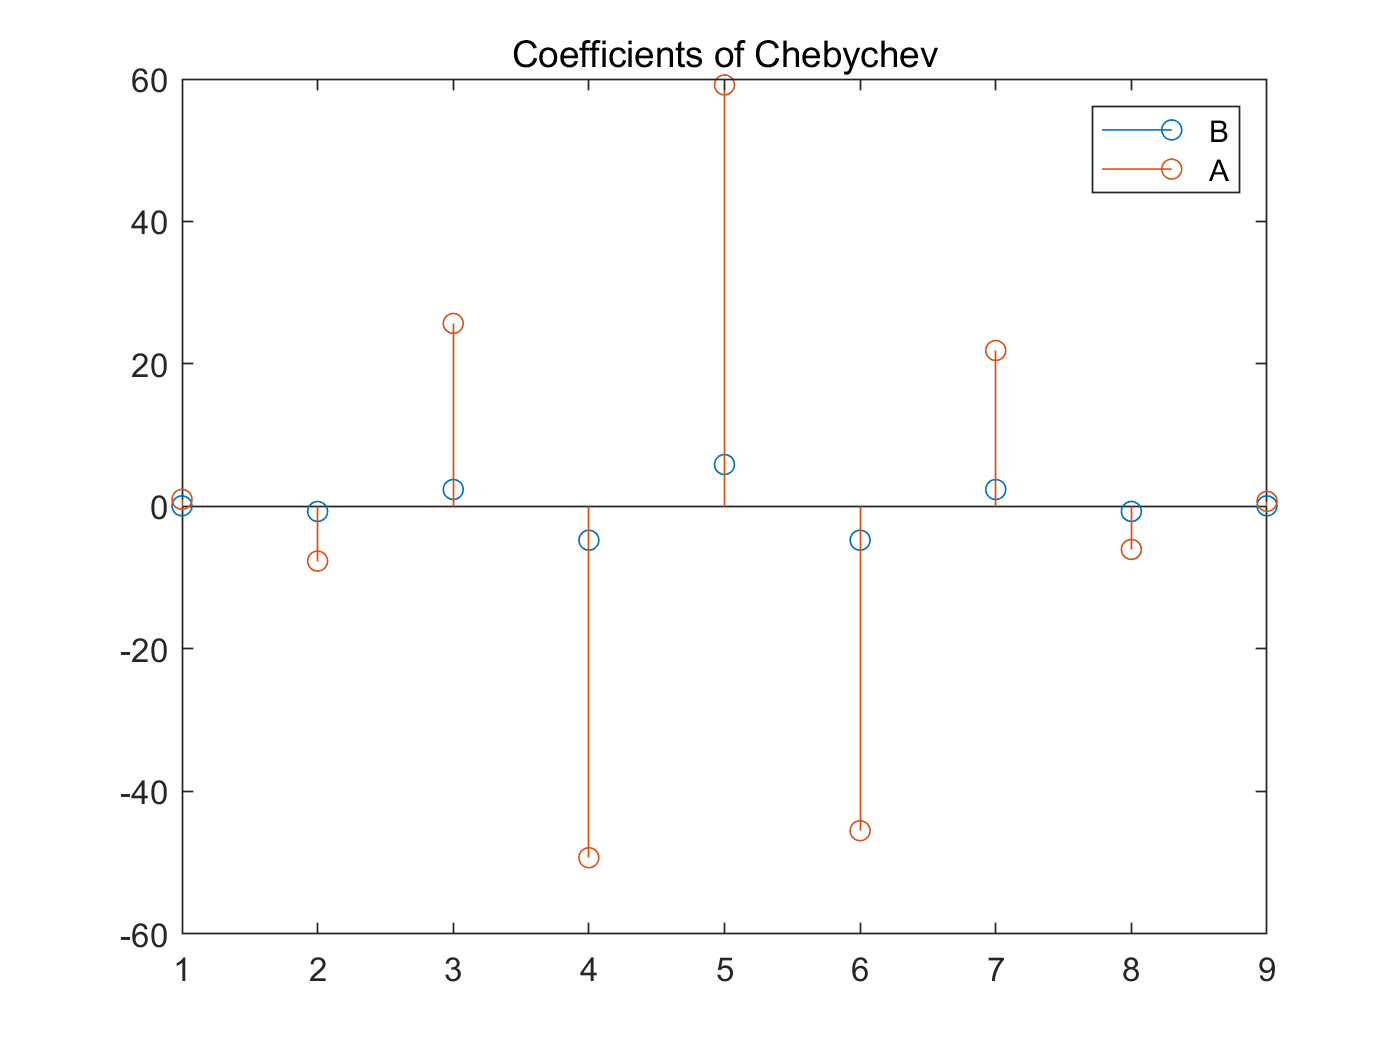

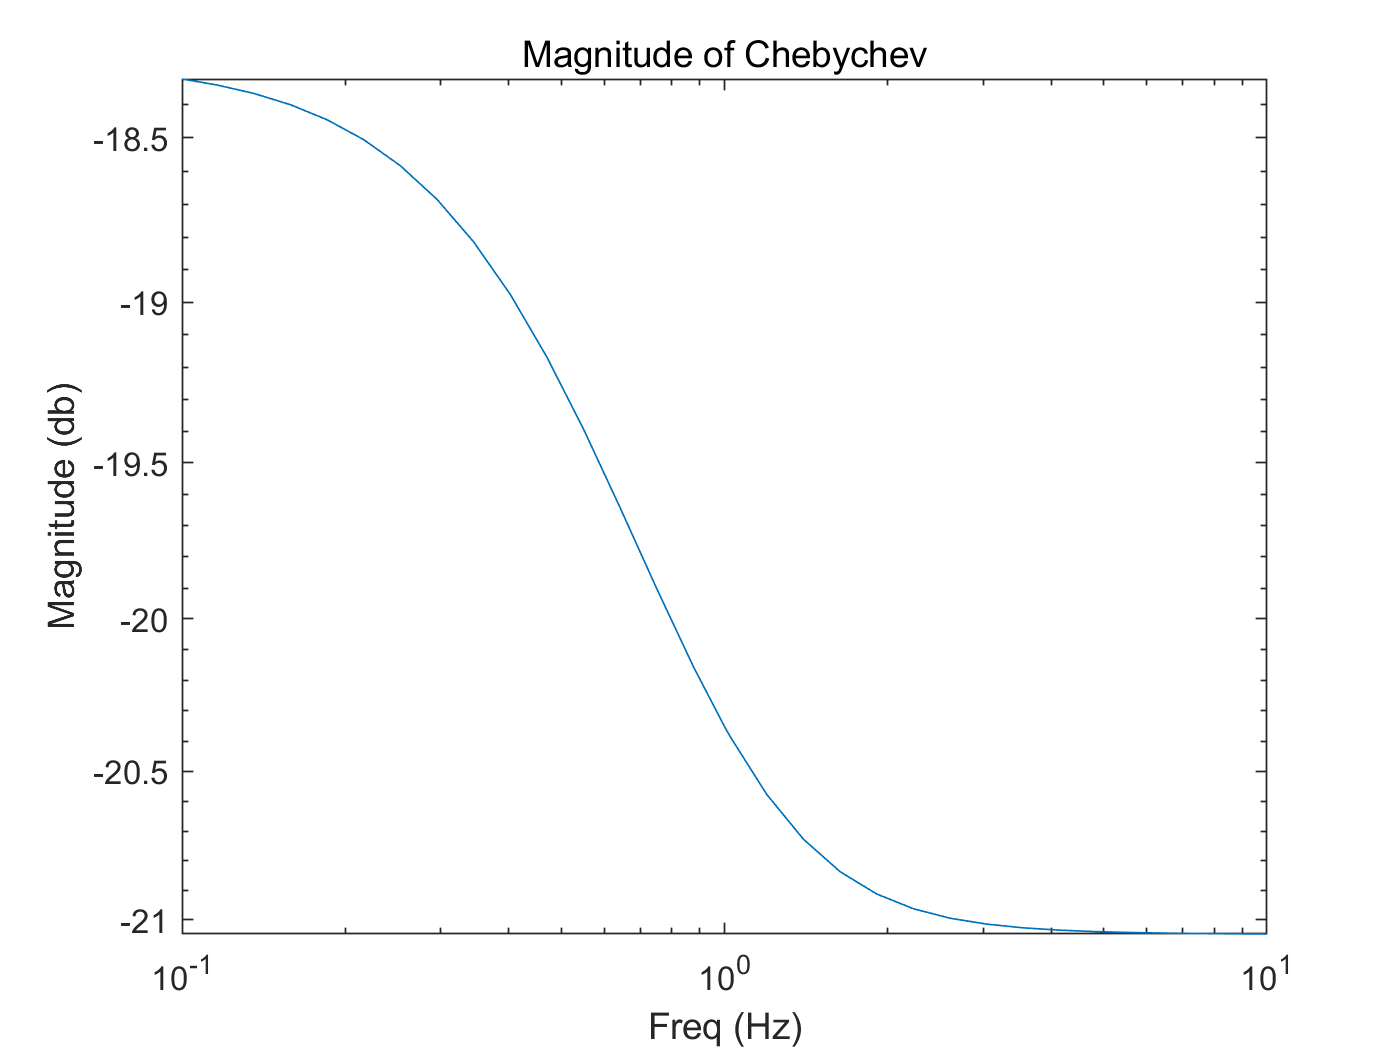

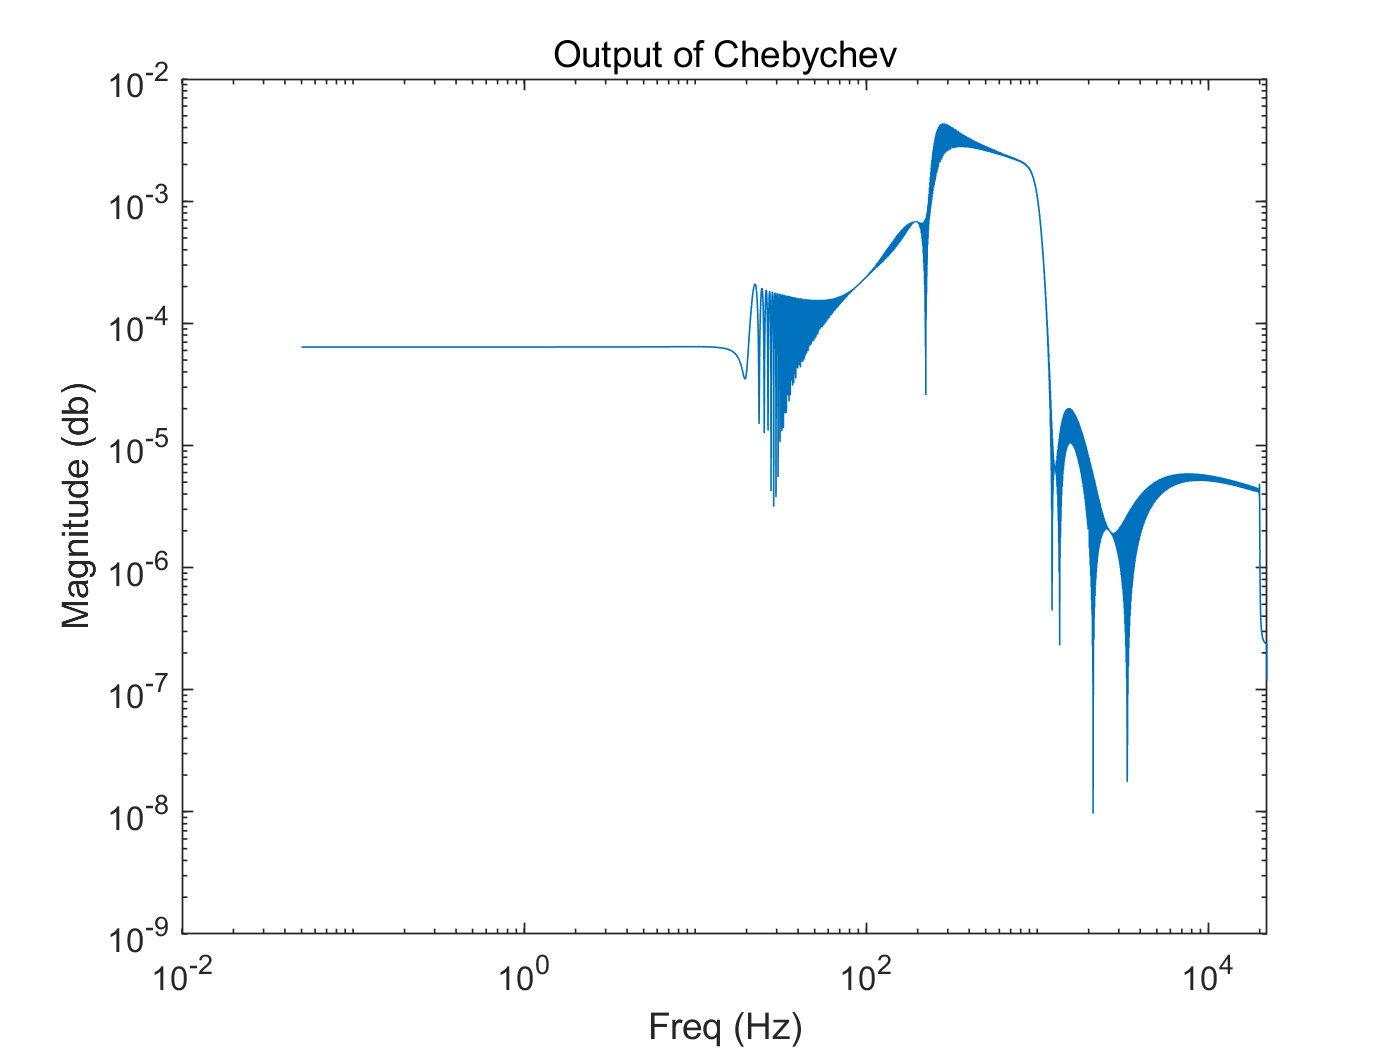

iir(SOS_C,G_C,"Chebychev")

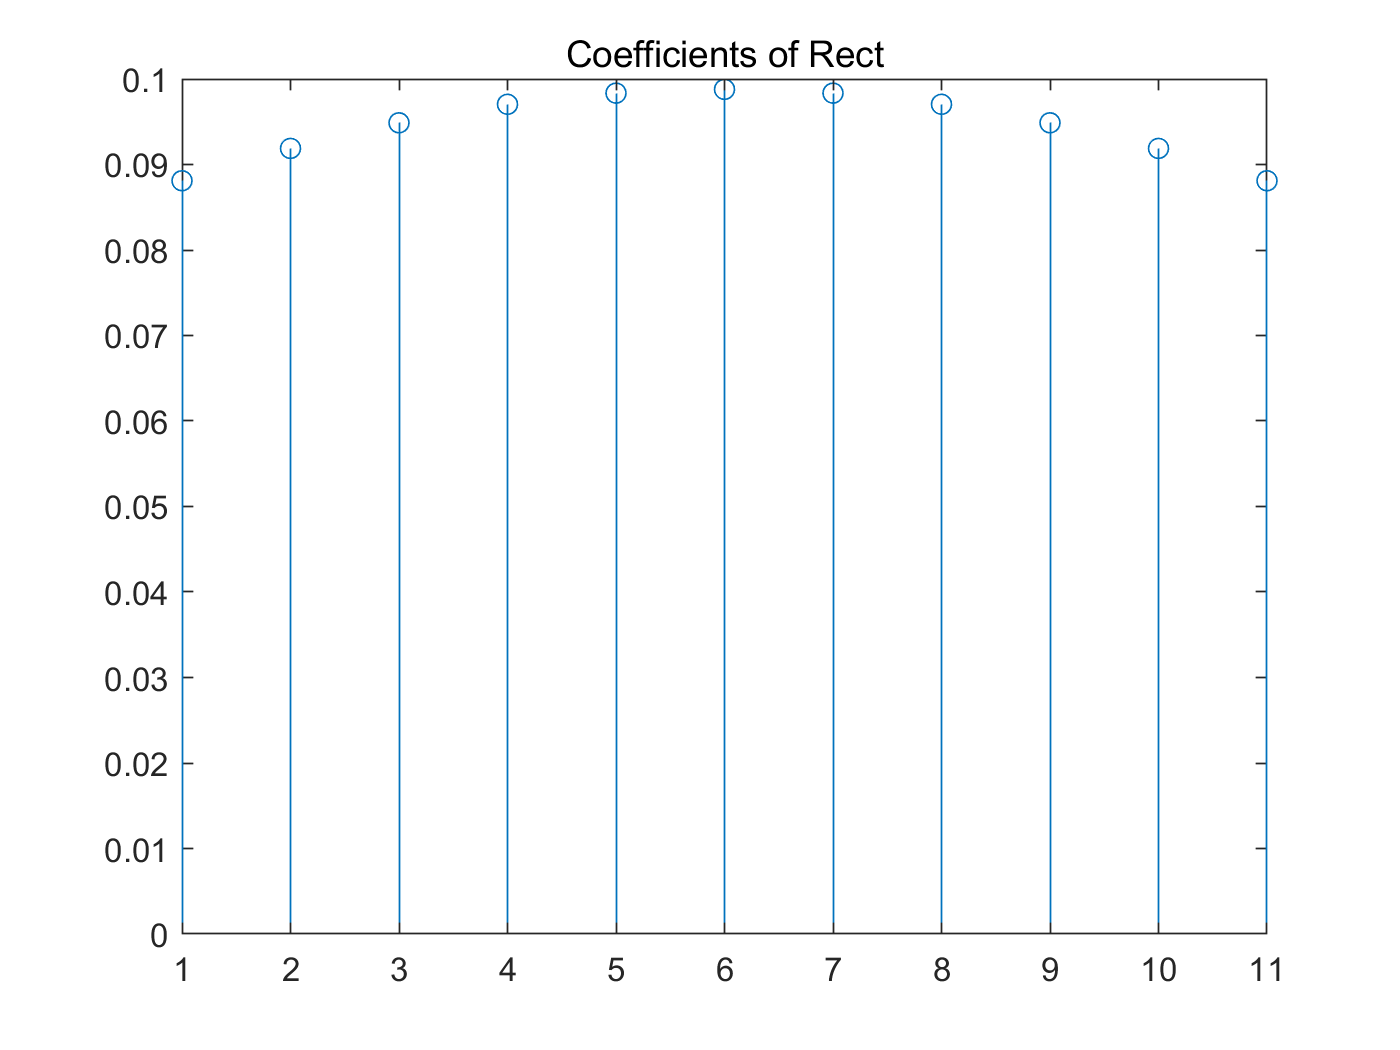

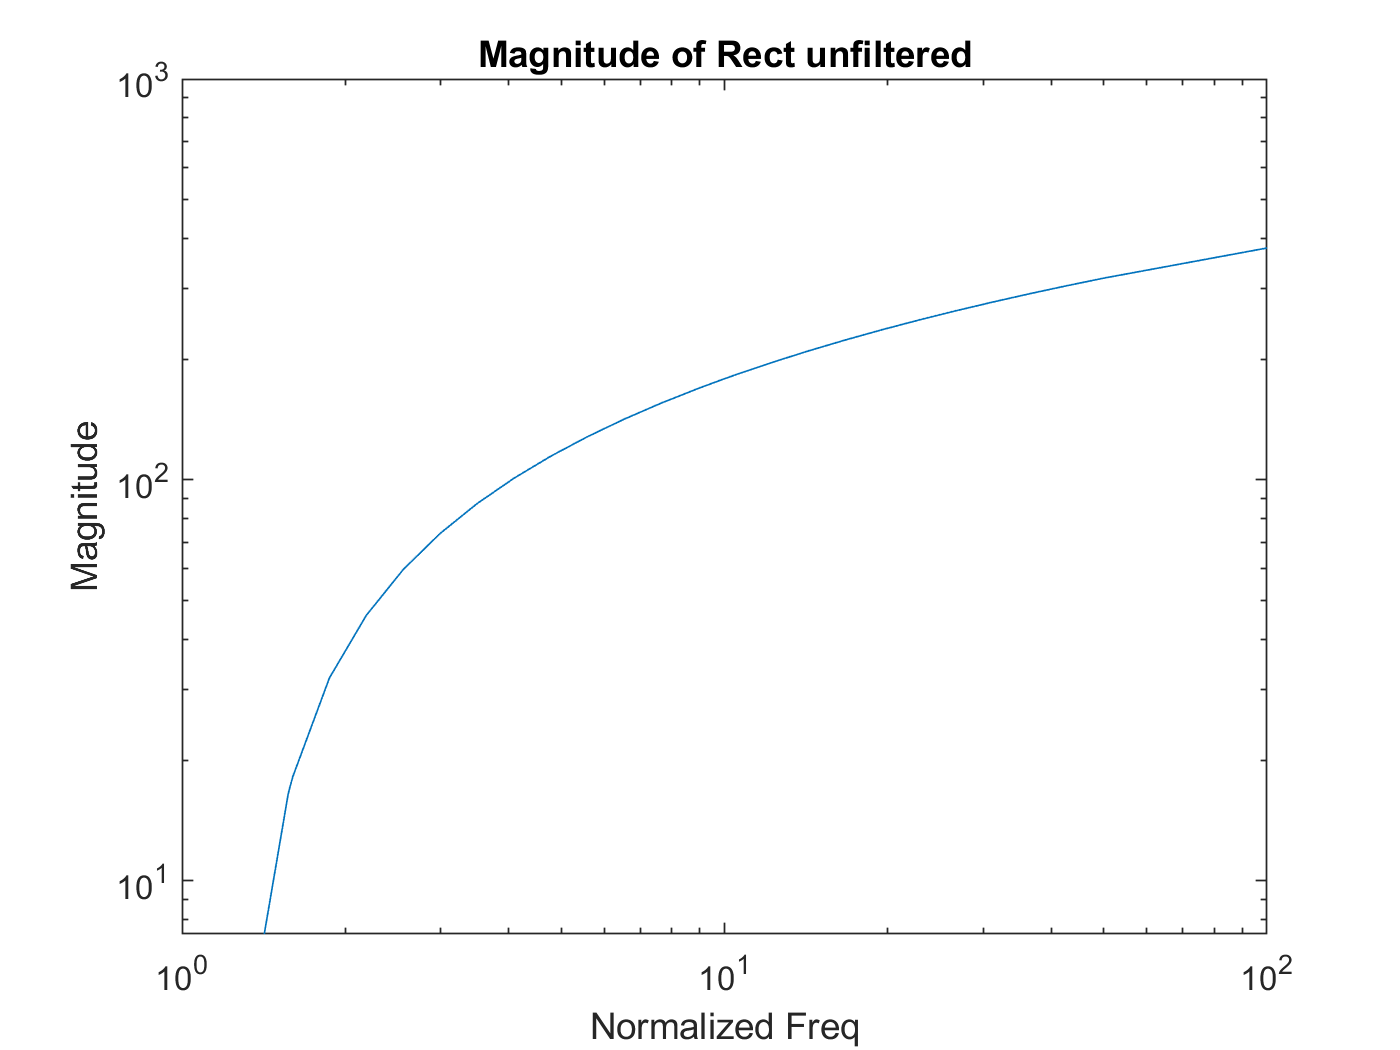

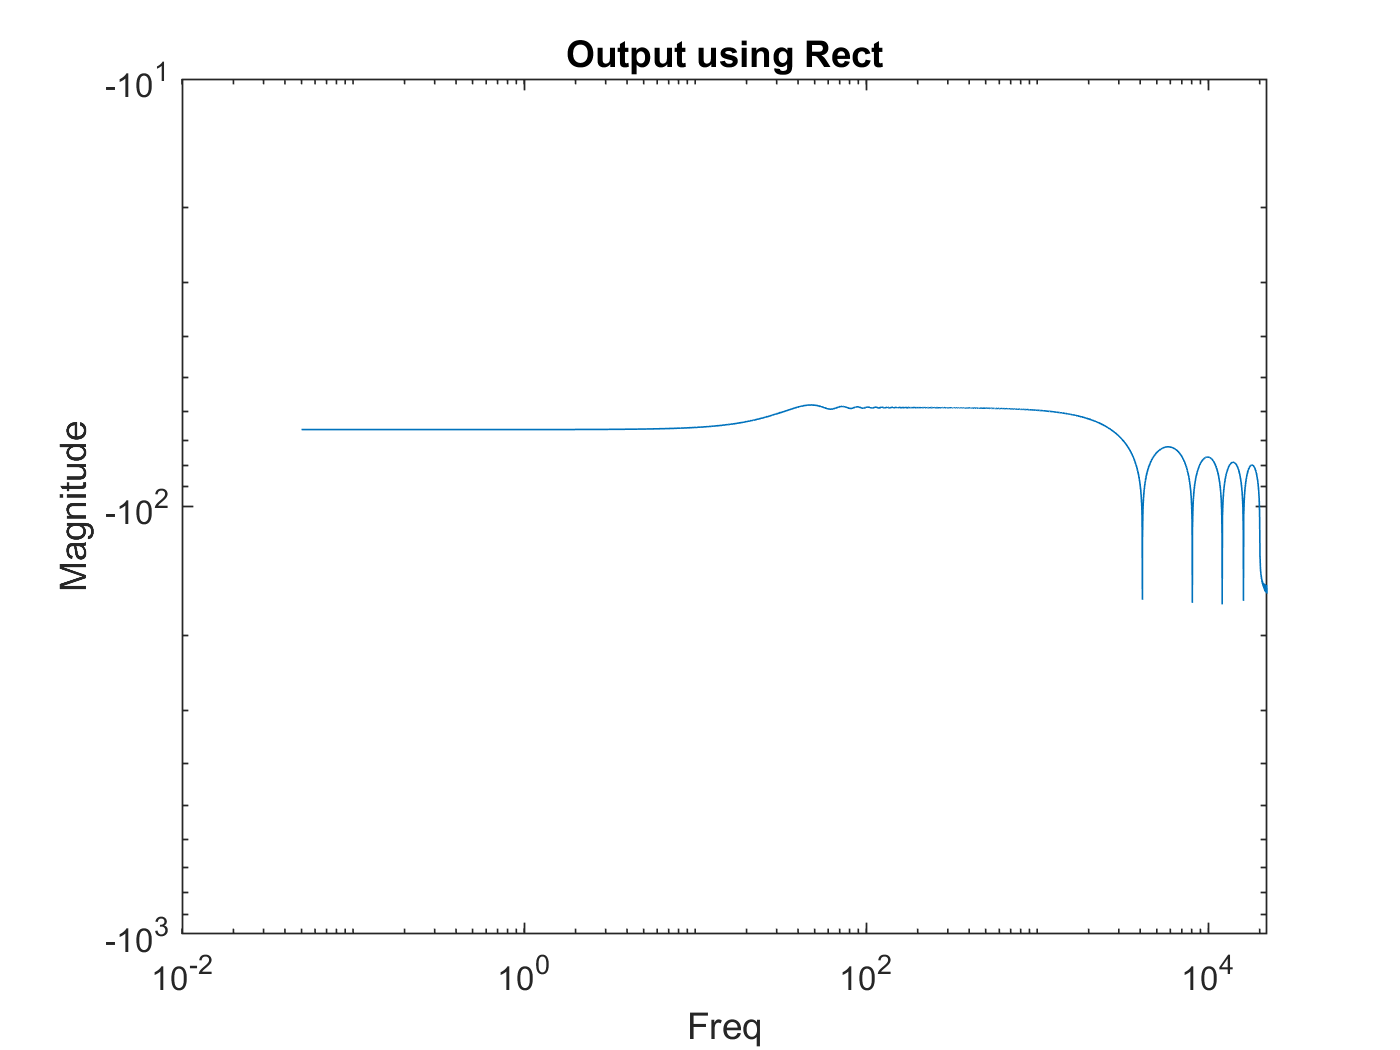

fir(B_Rect,"Rect")

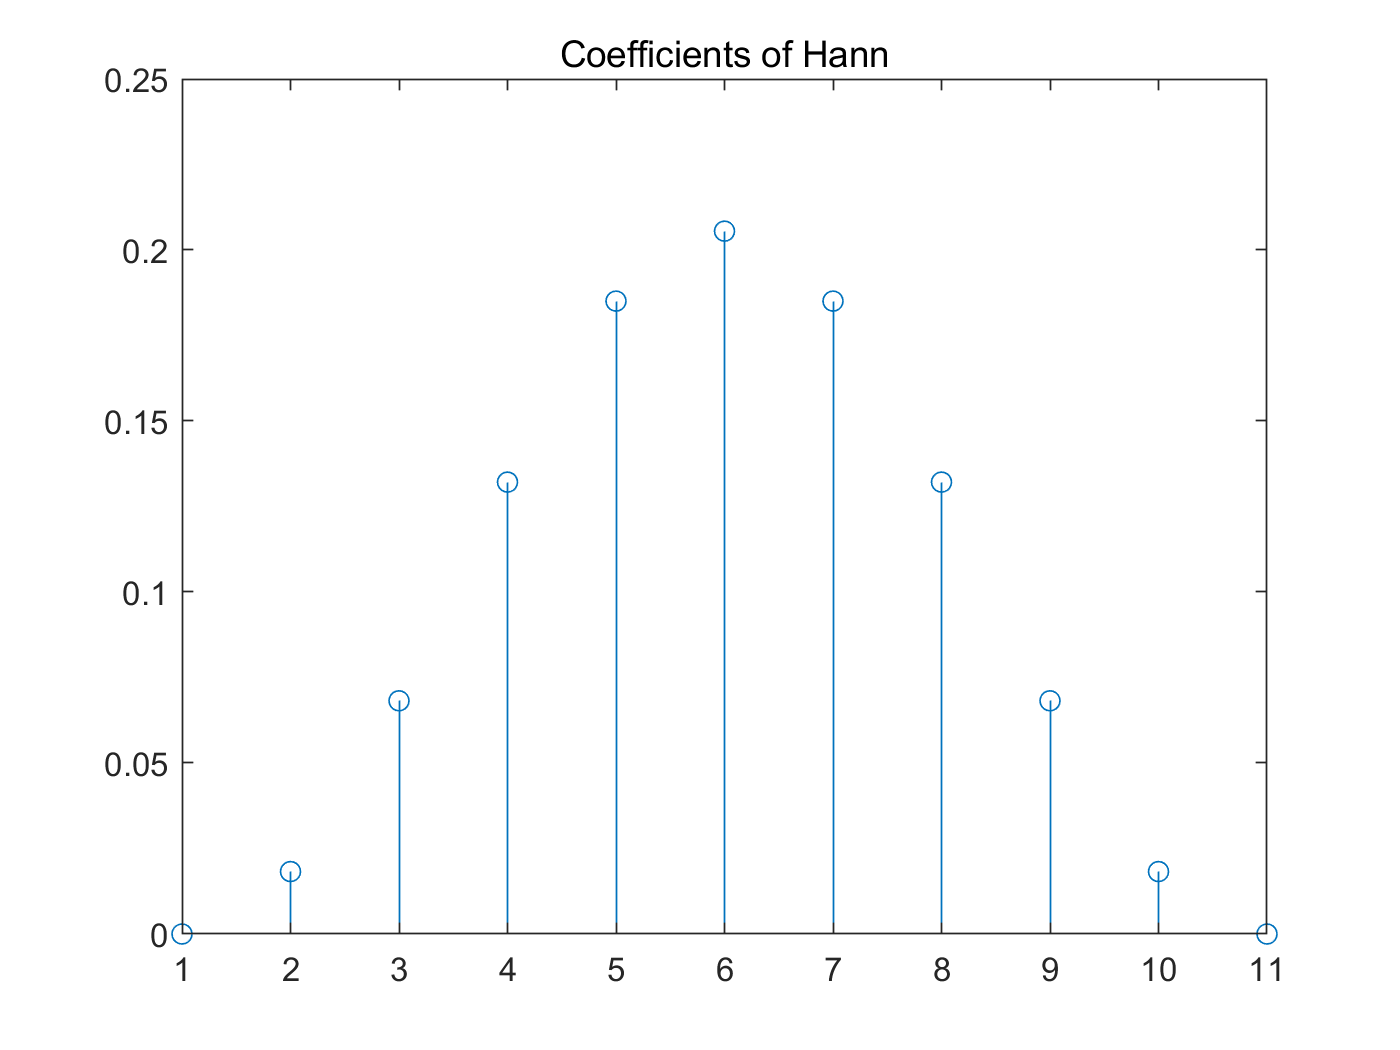

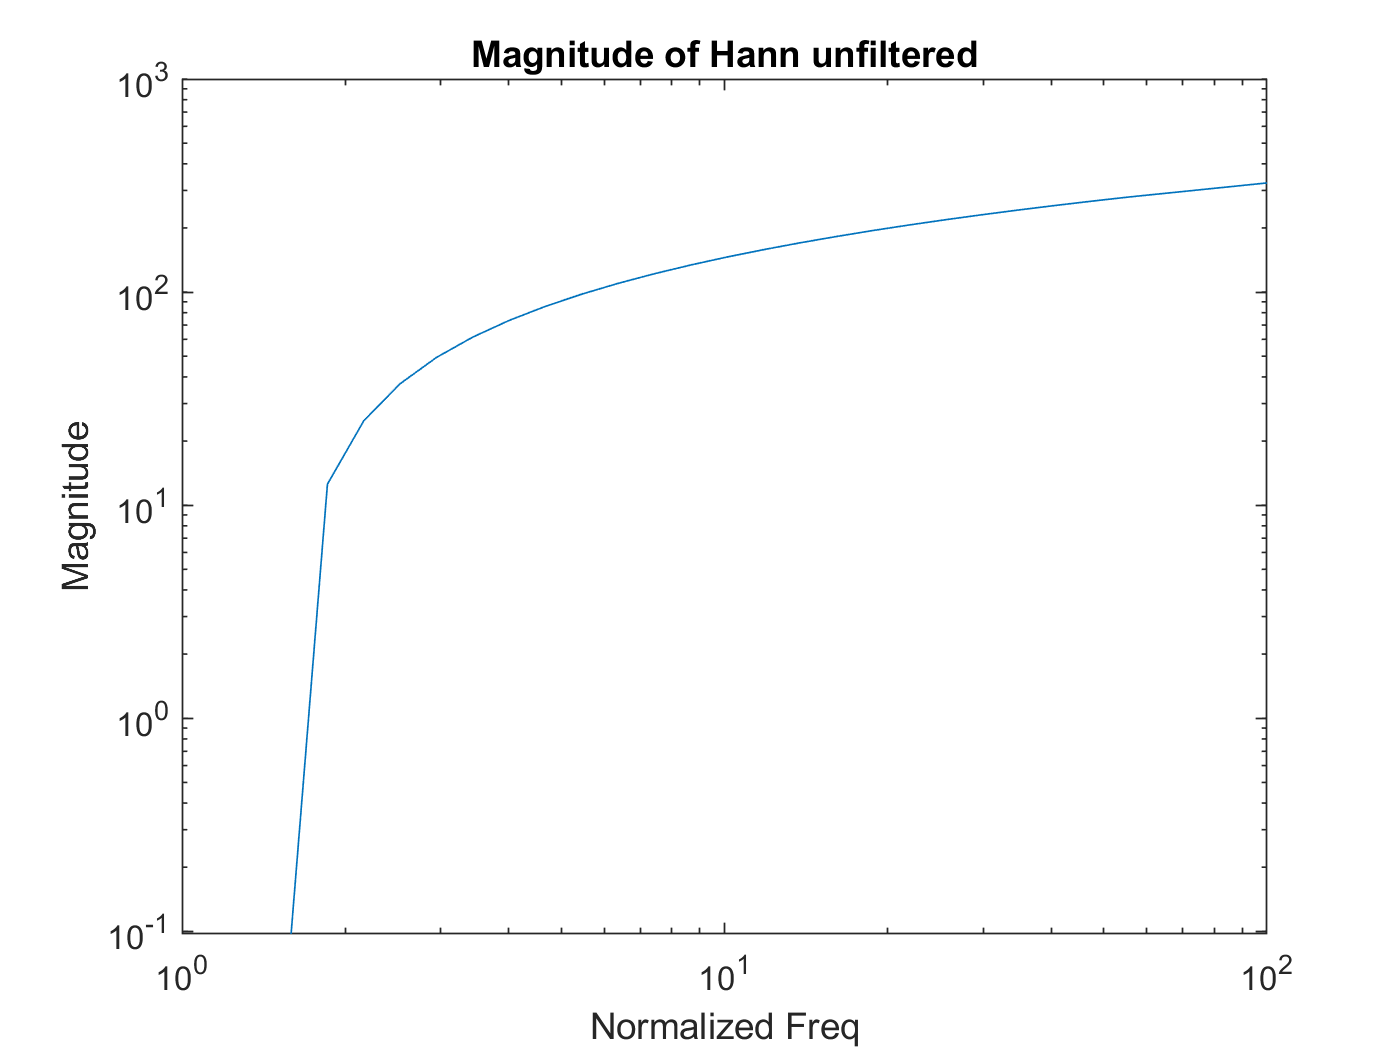

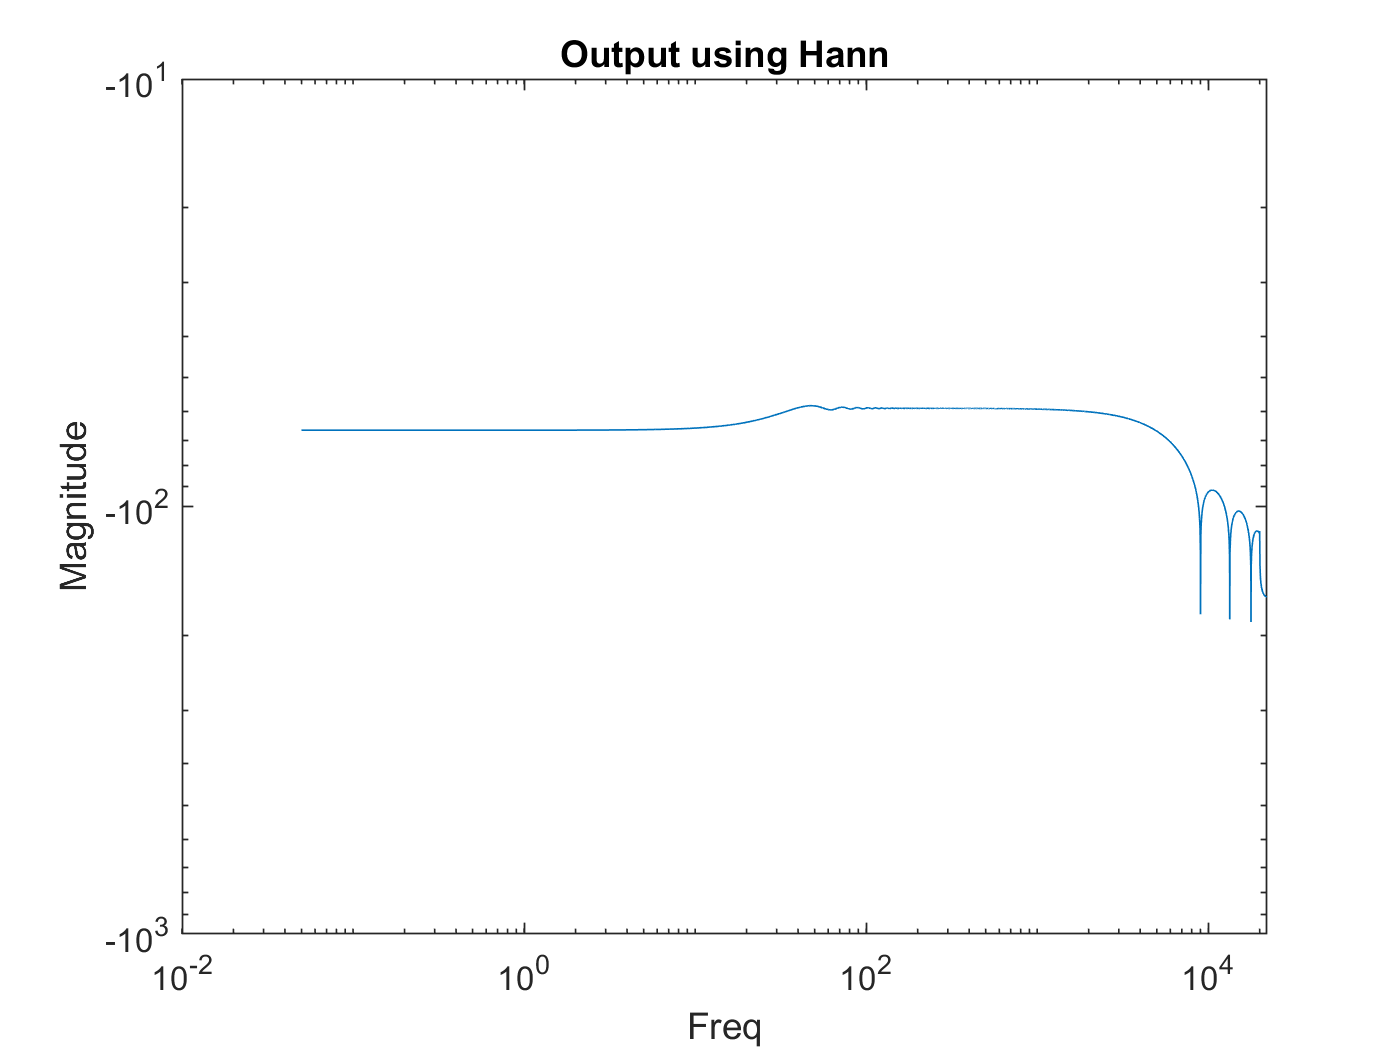

fir(B_Hann,"Hann")

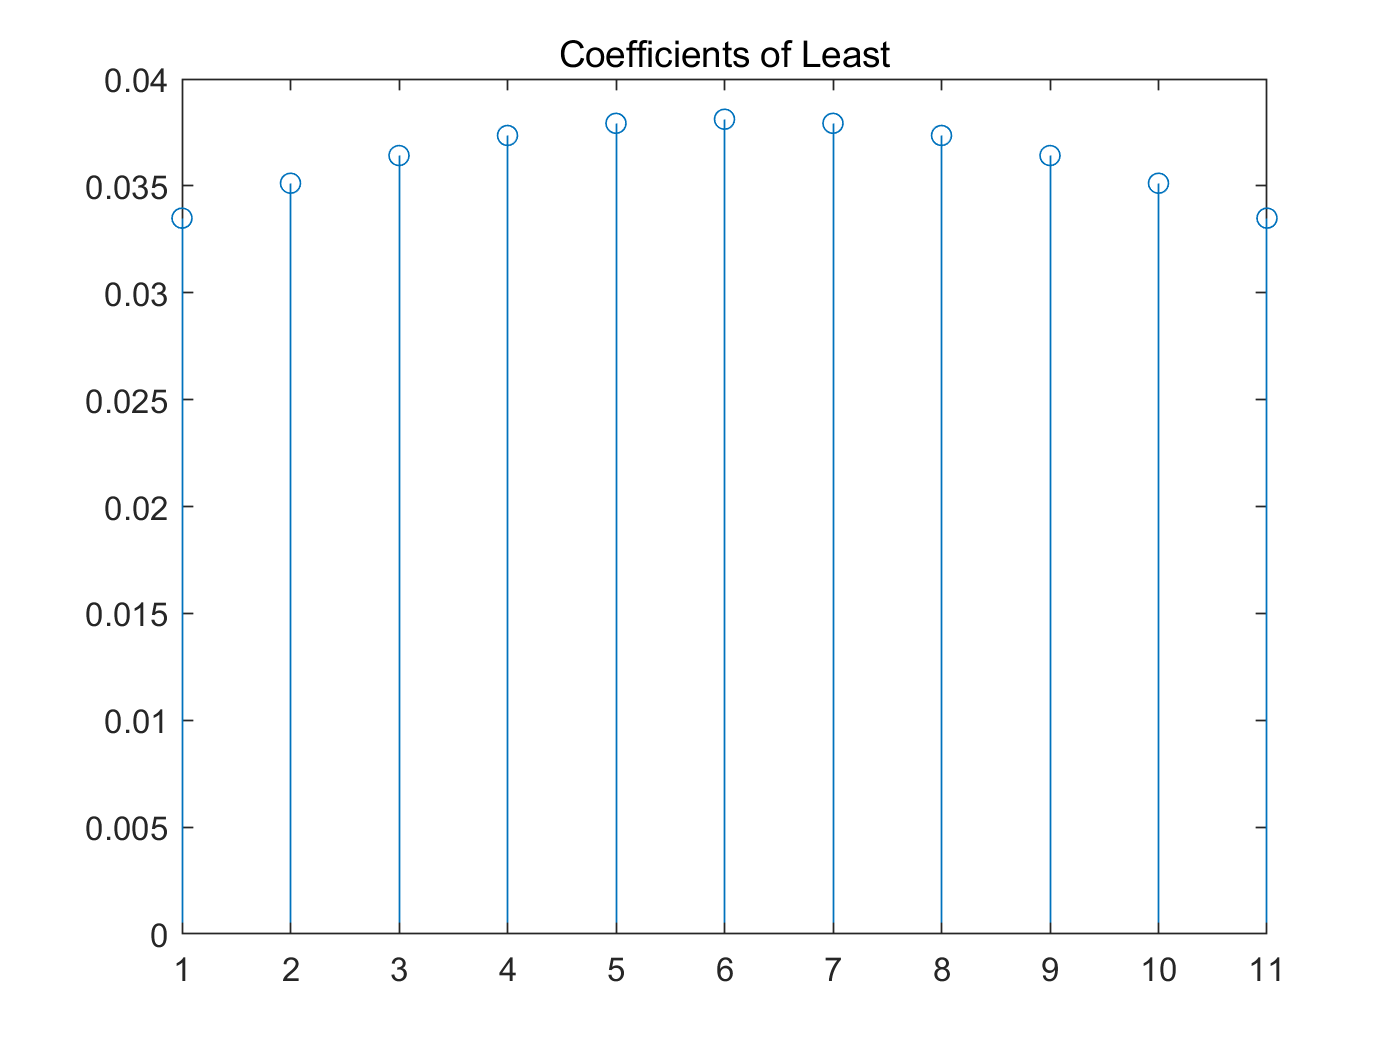

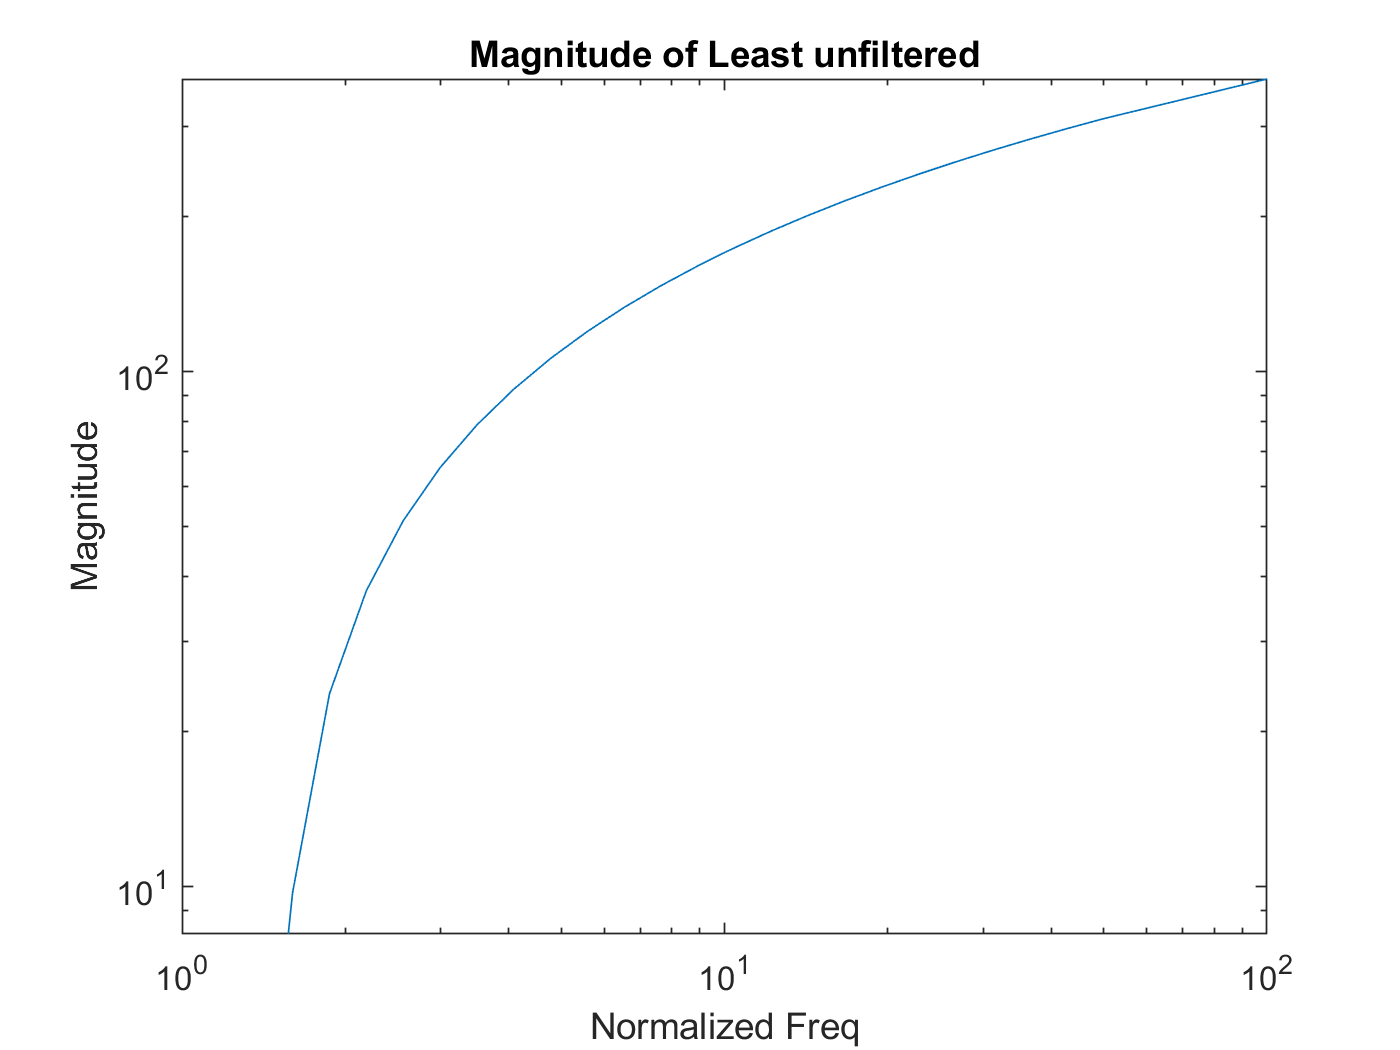

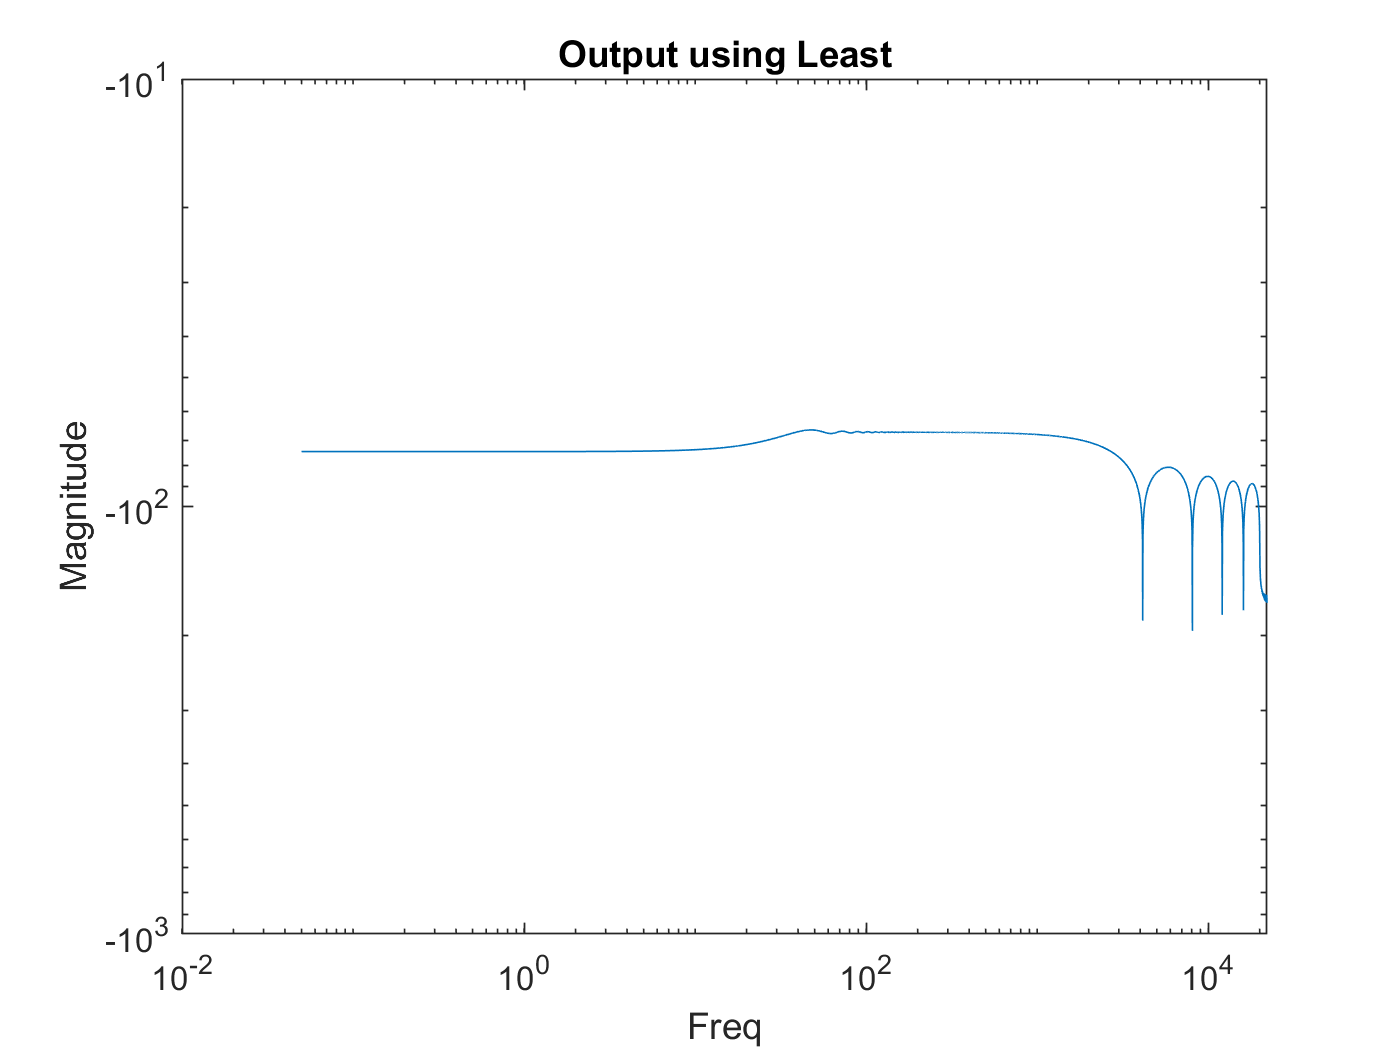

fir(Least,"Least")

**Anaylsis**

Task 1

- Butterworth - At about 2 seconds it hits its peak and keeps getting higher pitched as time increases, then at the last second fades away.

- Hann - Progressibly gets louder and rapid very quickly until around the 4 second mark. Then quickly fades away.

- Least - The most quiet filter. Slowly gets louder until around the 3 second mark and progressively gets a higher pitch until it fades away.

- Elliptic - At about 4 seconds it gets very loud and hits its peak, then drops off. Then later at around 10 seconds it gets much higher pitched and slowly fades away.

- Chebychev - At about 5 seconds it hits its peak, then starts to fade away, then roughly 5 more seconds later it spikes back up again. 

- Rectangle - Progressly gets higher pitched and fades away at the last second. Hits its peak around the 3 second mark.

Task 2 

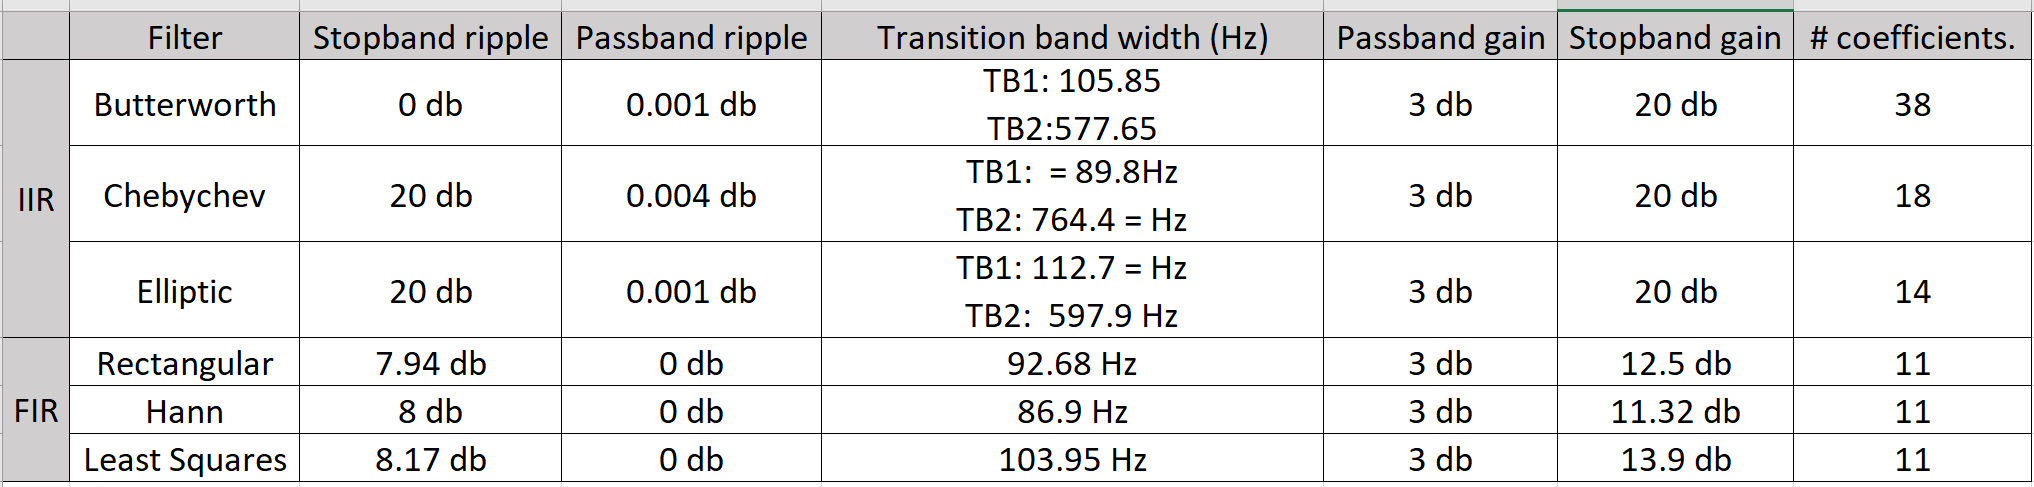

Task 3

**In general, can you provide insights as to context where it may be appropriate to apply FIR filters in preference to IIR filters?**

Answer: FIR FIlters are chosen in preference to IIR filters due to them having a linear phase response, and can be designed for any needed frequency response. FIR filters are chosen for applications like, audio processing, and signal synchronization. This is due to them being causal and stable.

The functions below were used to make the FIR and IIR filters.

function i = iir(x,y,audio)
[x_log, fs_log] = audioread("audiocheck.net_sweep20-20klog.wav");

[B, A] = sos2tf(x, y);
figure()
stem(B)
hold on
stem(A)
subtitle("Coefficients of " + audio)
legend('B','A')
figure()
hz = tf(B,A);
[mag,phase,omega] = bode(hz);
bode_plot = squeeze(mag2db(mag));
loglog(omega,bode_plot);
ylabel('Magnitude (db)');
xlabel('Freq (Hz)');
subtitle('Magnitude of ' + audio);
figure();
z = filtfilt(x,y,x_log);
Y = fft(z');
L = length(Y);
f = fs_log*(0:(L/2))/L;
P2 = abs(Y/L);
P1 = P2(1:(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
loglog(f, P1)
ylabel('Magnitude (db)');
xlabel('Freq (Hz)');
subtitle('Output of ' + audio);

audiowrite(audio + '.wav',y,fs_log);
end

function f = fir(x,audio)
[x_lin, fs_lin] = audioread("audiocheck.net_sweep20-20klin.wav");

figure();
stem(x);
subtitle('Coefficients of ' + audio);

figure();
hz = tf(x,1);
[mag, phase, omega] = bode(hz);
bode_plot = squeeze(mag2db(mag));
loglog(omega,bode_plot);
title('Magnitude of ' + audio);
ylabel('Magnitude');
xlabel('Normalized Freq');

figure();
y=filter(x,1,x_lin);
Y = fft(y');
L = length(x_lin);
f = fs_lin*(0:(L/2))/L;
P2 = abs(Y/L);
P1 = P2(1:(L/2)+1);
P1(2:end) = 2*P1(2:end);
bode_plot=mag2db(P1);
loglog(f,bode_plot);

title('Output using ' + audio);
ylabel('Magnitude');
xlabel('Freq');

audiowrite(audio + '.wav',y,fs_lin);
end

function x = xaxis()
L = length(x_log);
Y = fft(x_log);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);

f = fslog*(0:(L/2))/L;

bode_plot = P1;

loglog(f, bode_plot);

end

Below are both my functions, myfft and myifft. They are attached this way since this file must be submitted as one PDF.

myfft.m

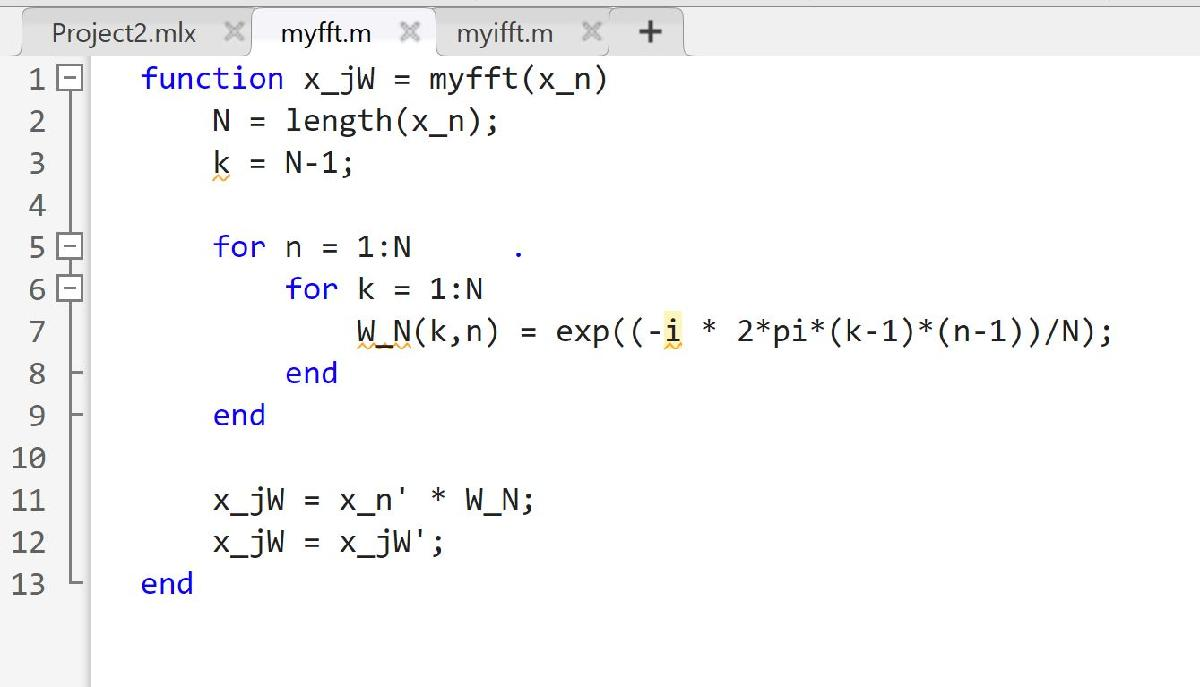

myifft.m